# Numerical Solution of the model for firing nerve cells

$\left\lbrace \begin{array}{c}
\frac{\textrm{d}}{\textrm{d}t}x=y+x-\frac{x^3 }{3}+I\\
\frac{\textrm{d}}{\textrm{d}t}y=-x+a-\mathrm{by}
\end{array}\right.$ Fitzhugh and Nagamo's of the Hodgkin-Huxley model

where a and b are constant satisfying certain conditions and I is a parameter. 

x represents the excitability of the system and y is a combination of other forces that return the system to rest.

## Simplification and Study of linearized system

$\left\lbrace \begin{array}{c}
\frac{d}{dt}x=y+x−\frac{1}{3}x^3 \\
\frac{d}{dt}y=−x+0\ldotp 056−0\ldotp 064y
\end{array}\text{   }\right.$, linearization around the origin $\Rightarrow \left\lbrace \begin{array}{c}
\frac{d}{dt}x=y+x\\
\frac{d}{dt}y=−x−0\ldotp 064y
\end{array}\text{ }\right.$


% initial conditions: -> x0, y0
a = 0.056; b = 0.064;
x0 = 0.1; y0 = 0;
X0 = [x0; y0];
tspan = [0, 5]; % 0 to 5 seconds
n = 10;
% number of points ns = 5:1000
ns = 5:1000;

## Phase Portrait

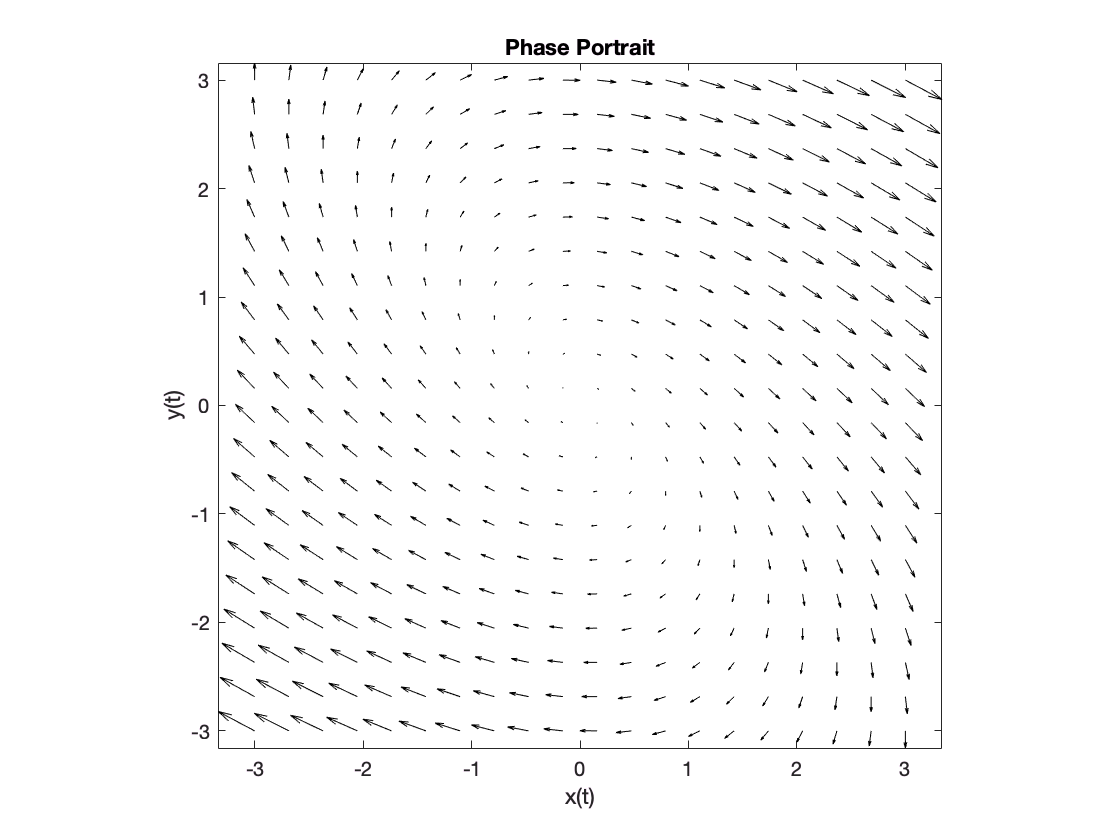

%% Phase Portrait: plot of a vector field 
% which qualitatively shows how the solutions to these equations will go from a given starting point
f_linear = @(t, X) [X(1)+X(2); -X(1)-b*X(2)];
% phase protrait on linearized system
ode_project.portrait_plot(f_linear, 3)

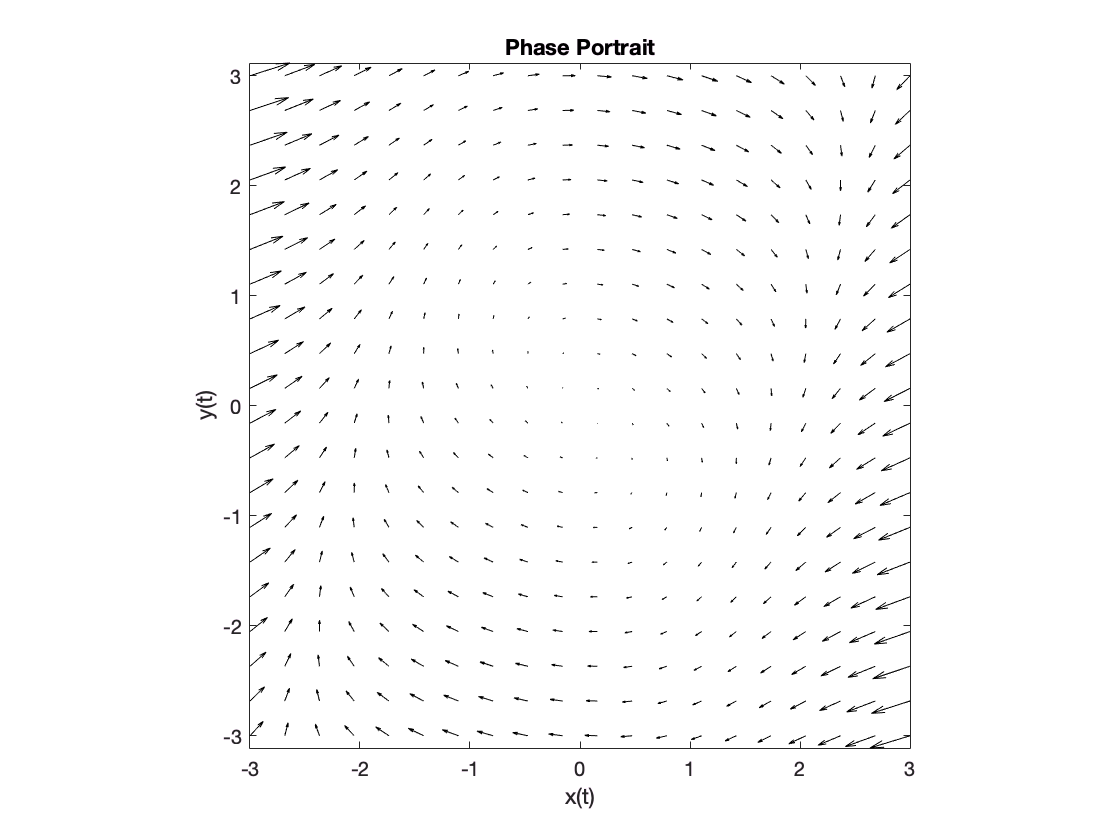

f_nonlinear = @(t, X) [X(1)+X(2)-(1/3)*X(1)^3; -X(1)+a-b*X(2)];
% phase portrait on non linear system
ode_project.portrait_plot(f_nonlinear, 3)

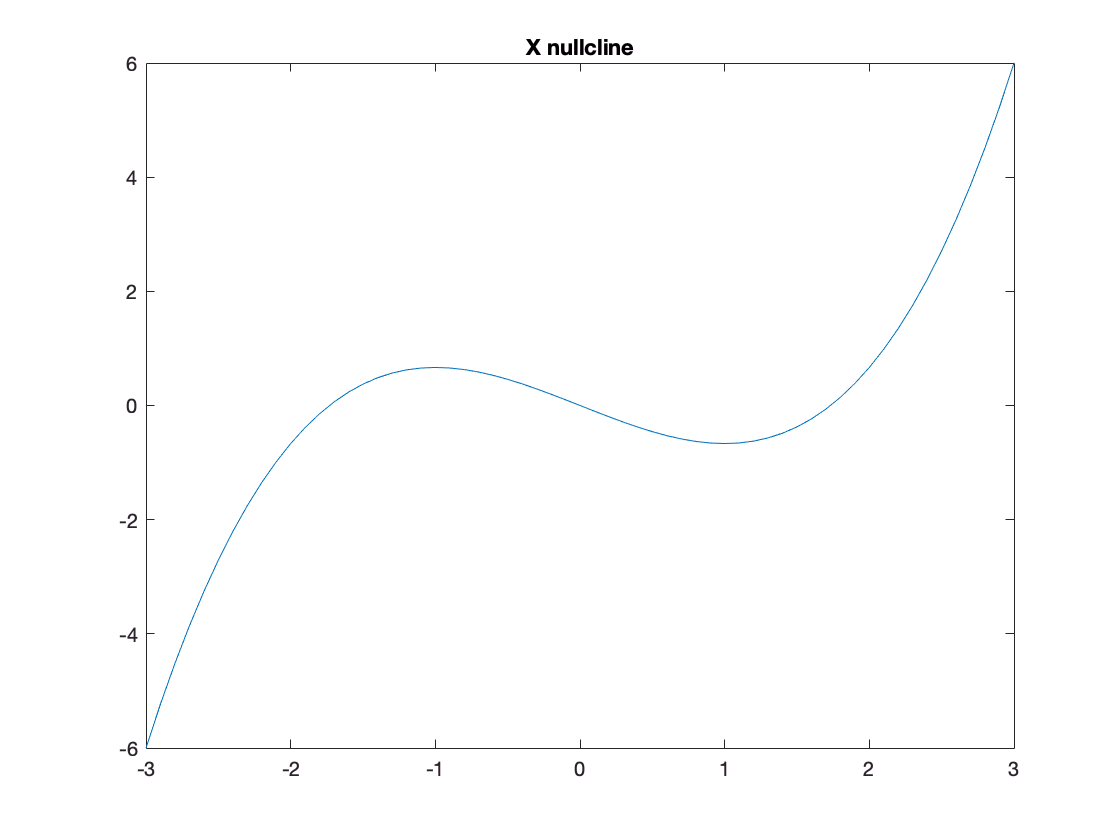

%nullcline
%x_nullcline
x=-3:0.1:3;
y = @(x) (1/3)*x.^3-x;
plot(x, y(x)); title('X nullcline')

## Eigein values and eigenvectors


$$\frac{d}{dt}X=\text{AX}\text{ }\text{where}\text{ }A=\left\lbrack \begin{array}{c}
1 & 1\\
−1 & −0\ldotp 064
\end{array}\right\rbrack \text{ }\text{and}\text{ }X=\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$$



$$X=c_1 *V_0 *e^{\lambda_2 t} \;+c_2 *V_1 *e^{\lambda_2 t} \;$$


A = [1 1; -1 -b];

## Analytical solution - linear system

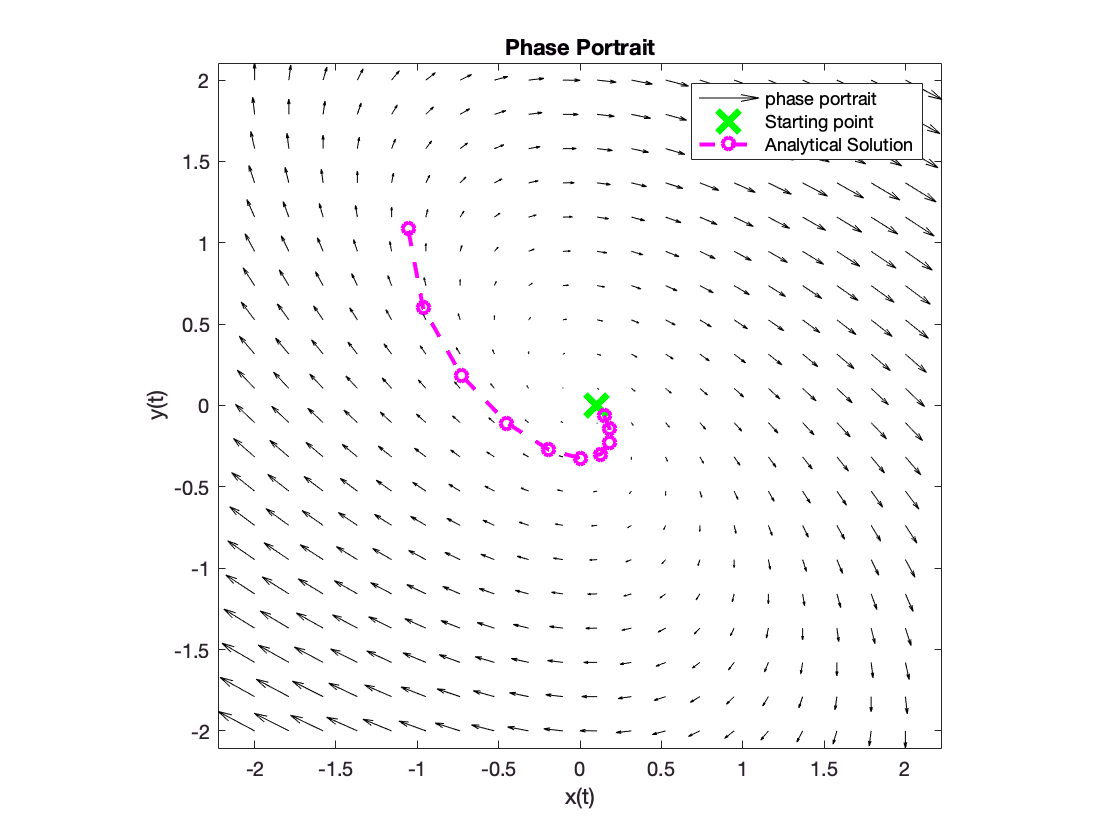


[~, analytical_sol] = ode_project.linear_exact_solution(A, X0, tspan, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')

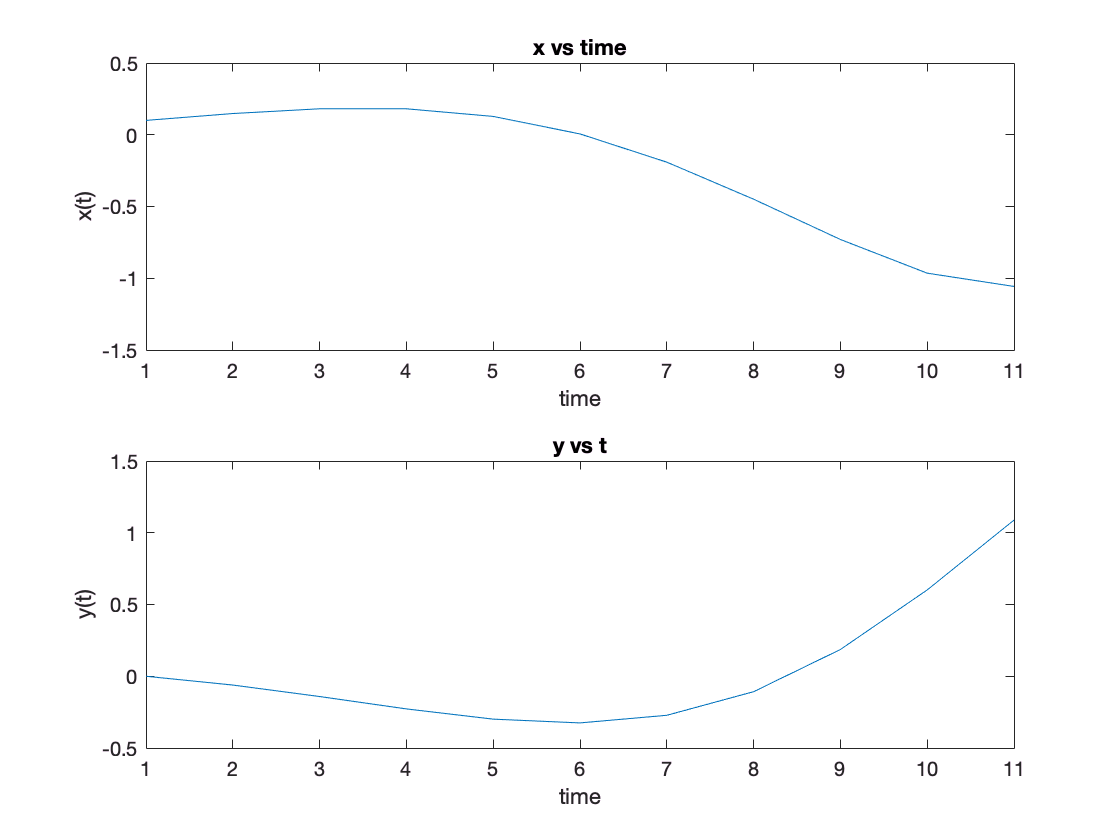

ode_project.plot_xy(analytical_sol)

## Analytical Solution - Non Linear system

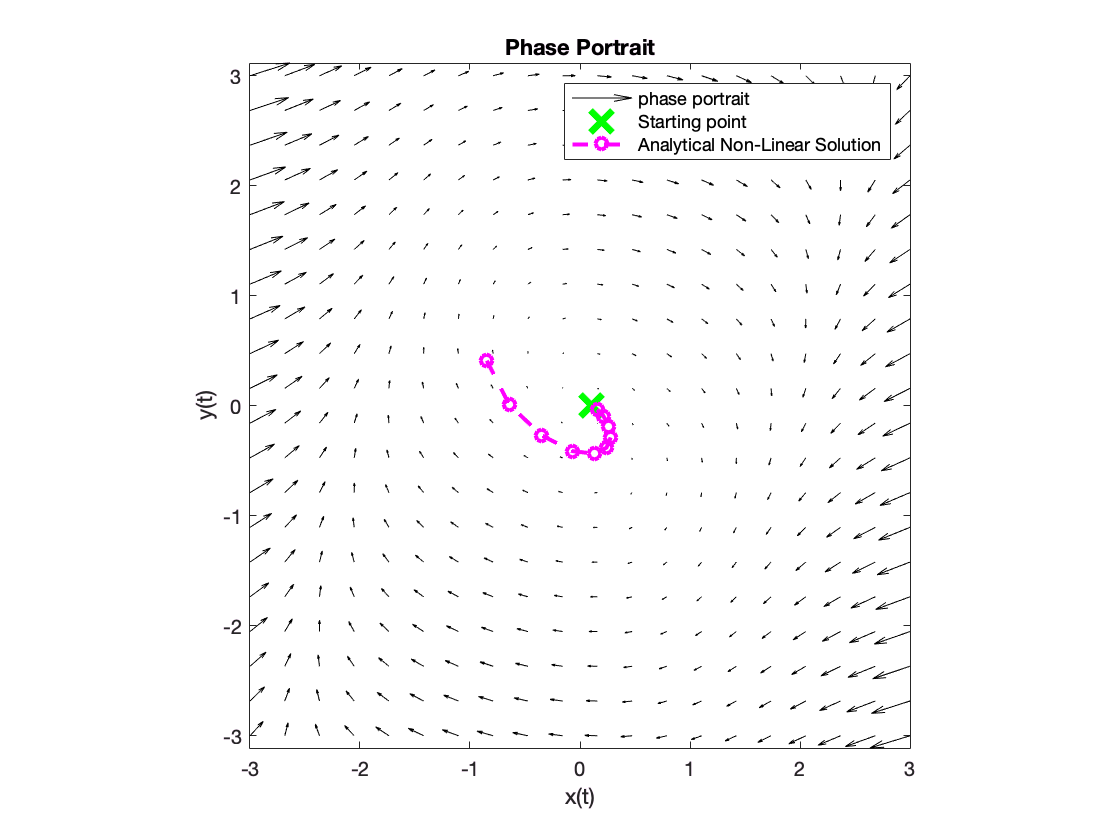


dt= (tspan(2)-tspan(1))/n;
[~, analytical_nlinear_res]=ode45(f_nonlinear, tspan(1):dt:tspan(2), X0);
ode_project.portrait_plot(f_nonlinear, 3)
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Non-Linear Solution')

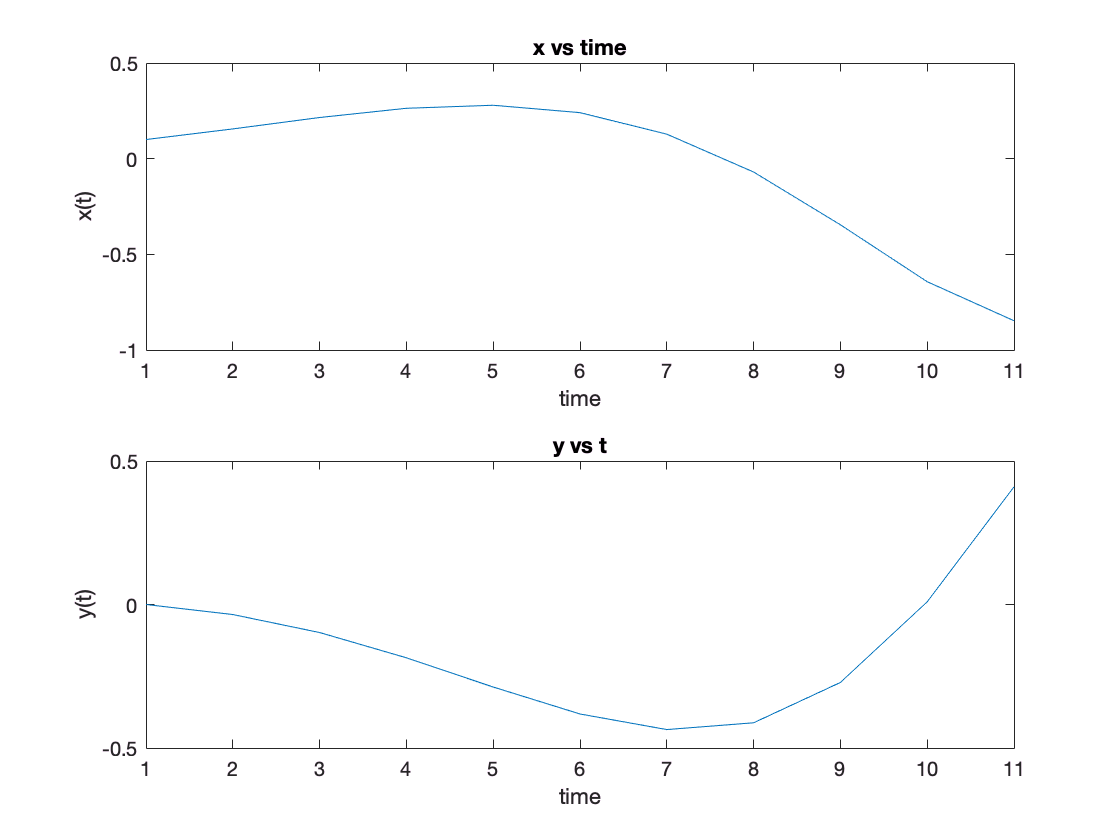

ode_project.plot_xy(analytical_nlinear_res')

## linear vs non linear analytical solution

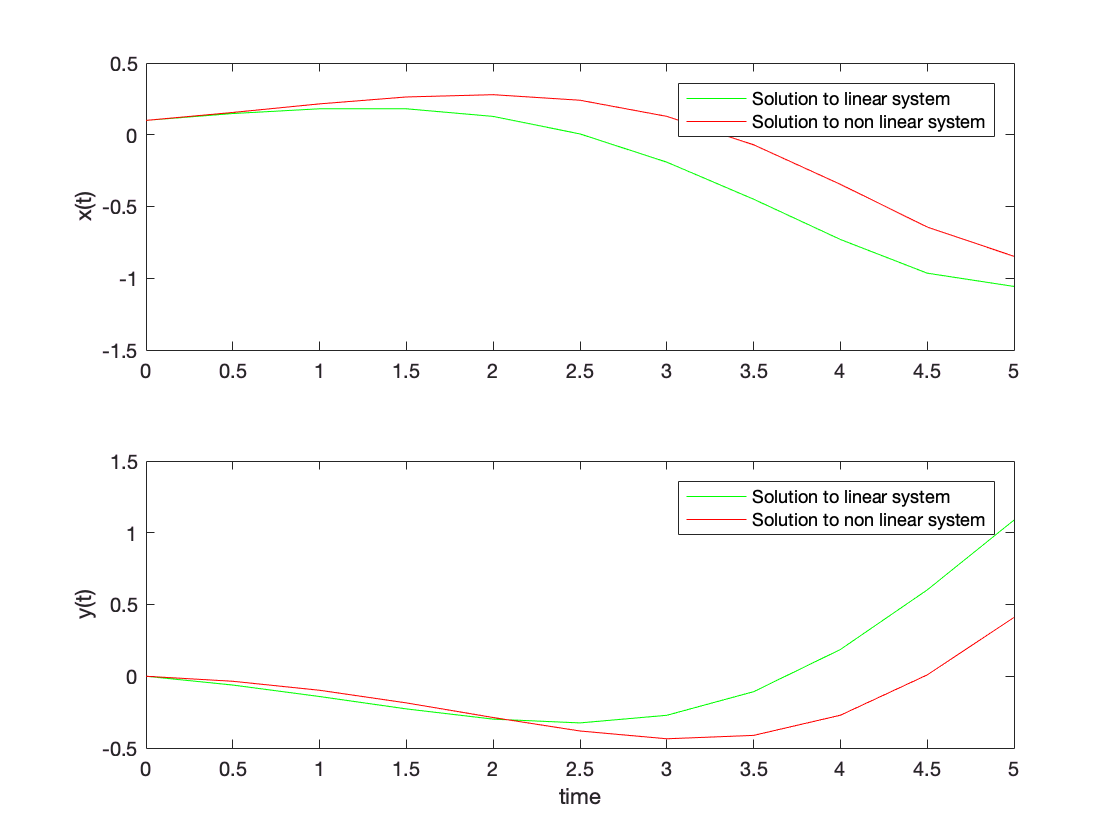


ode_project.plot_linear_vs_nlinear(analytical_sol, analytical_nlinear_res', tspan, n)

## Euler method

$\left\lbrace \begin{array}{c}
\frac{d}{dt}x=y+x−x^3 =f_1 \left(x,y\right)\text{ }\\
\frac{d}{dt}y=−x+a−by=f_2 \left(x,y\right)\text{ }
\end{array}\text{   }\right.$, $\left\lbrace \begin{array}{c}
x_{k+1} =x_k +f_1 \left(x_k ,y_k \right)*\Delta t\\
y_{k+1} =y_k +f_2 \left(x_k ,y_k \right)*\Delta t\;
\end{array}\right.$

## linear system

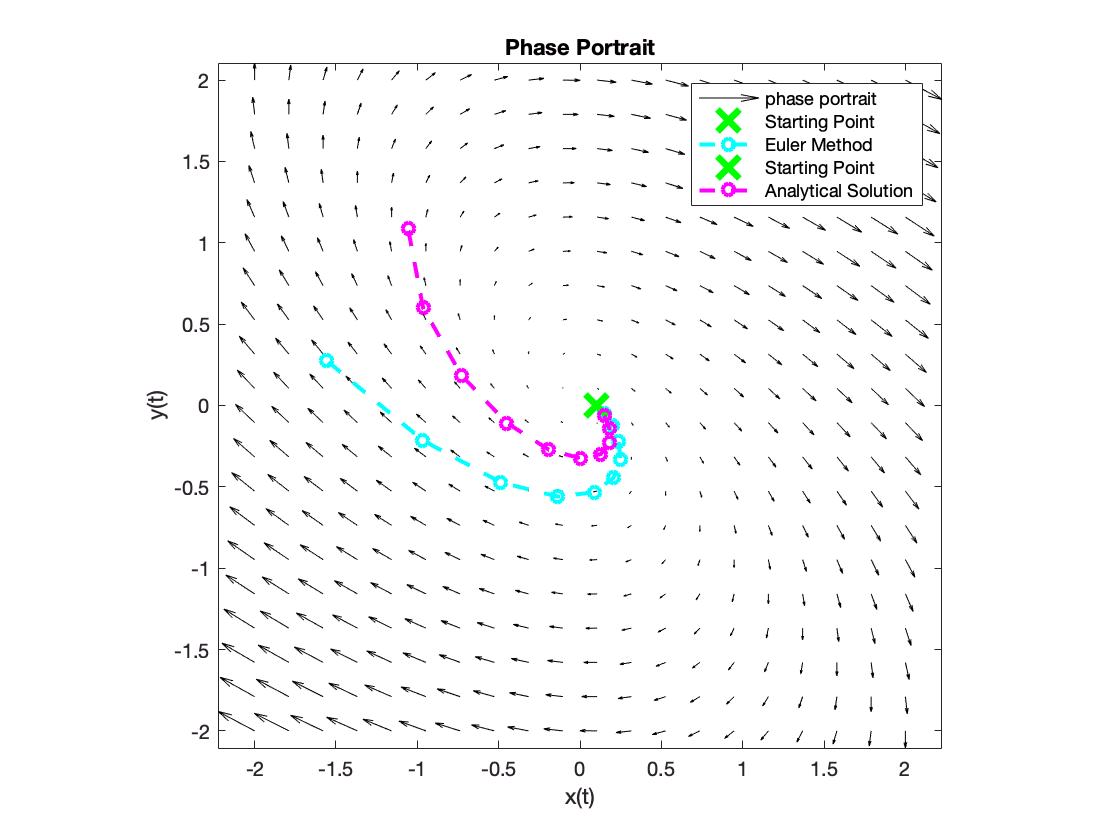


% f_linear = @(t, X) [X(1)+X(2); -X(1)-b*X(2)];
[~, euler_sol] = ode_project.Euler_ode(f_linear, X0, tspan, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(euler_sol, 'c--o', 'Euler Method')
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Euler Method', 'Starting Point','Analytical Solution')

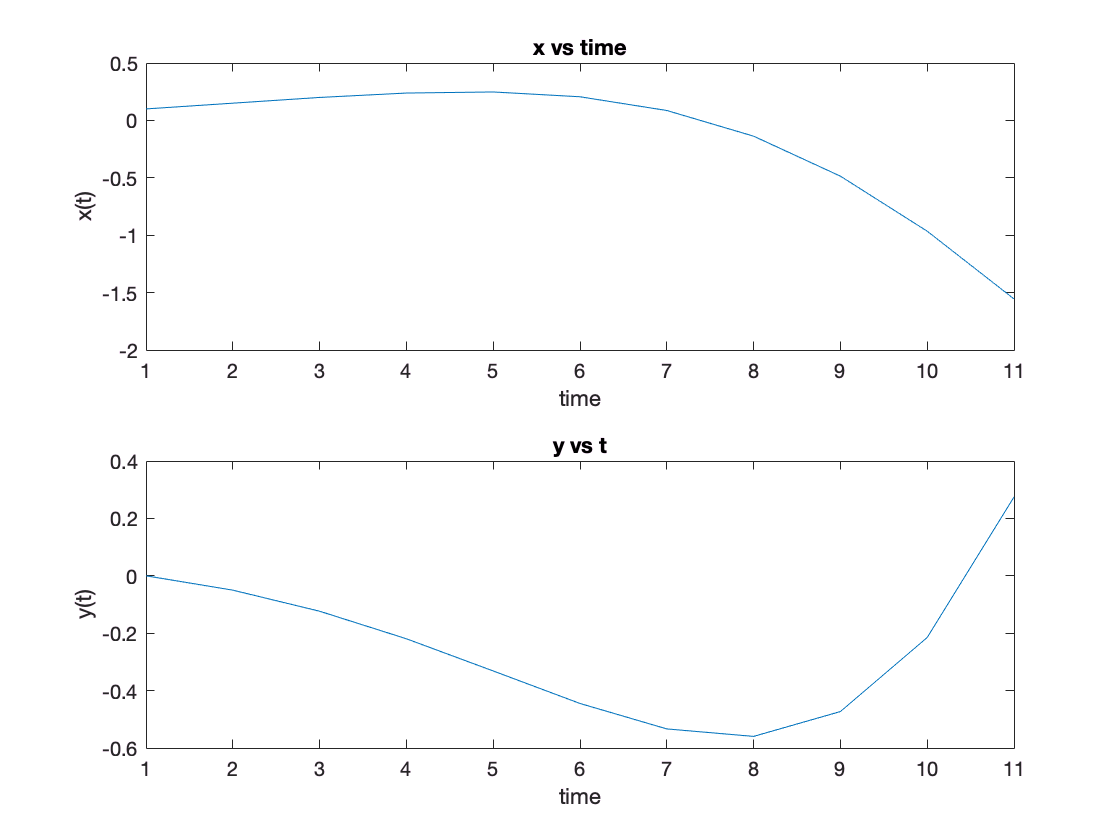

ode_project.plot_xy(euler_sol)

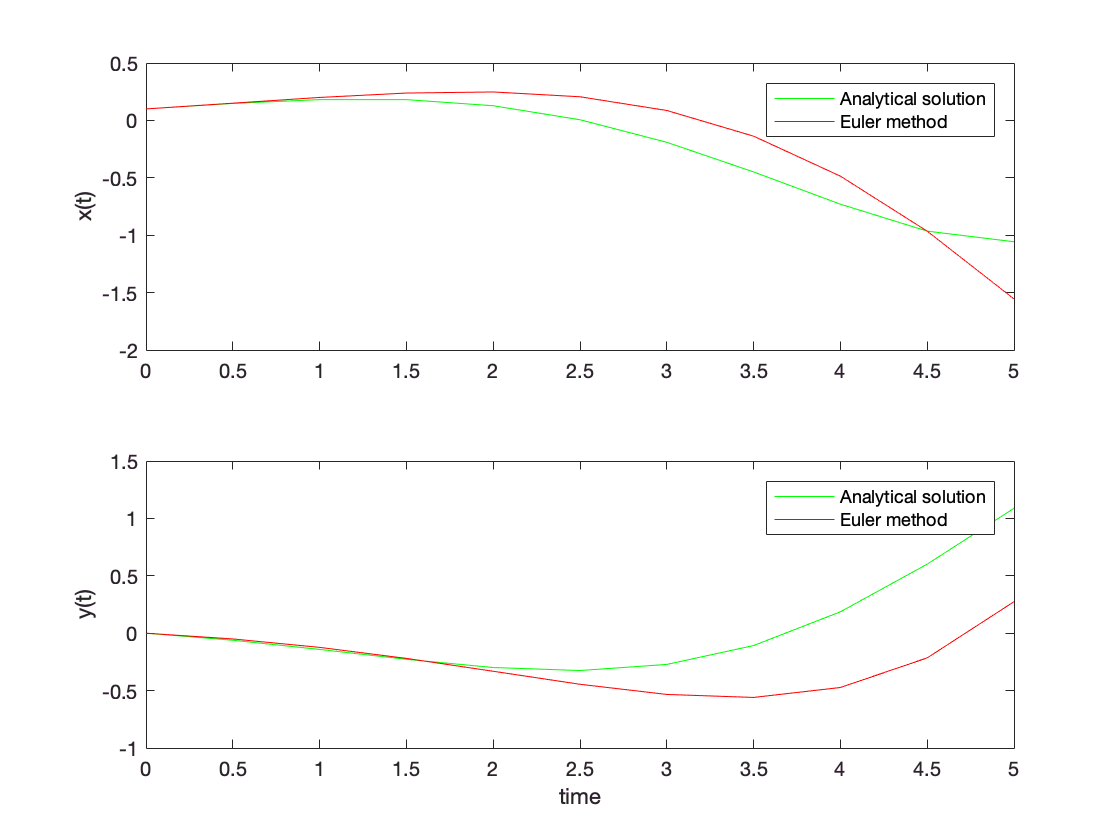


ode_project.plot_comparison(analytical_sol, euler_sol, tspan, n, 'Euler method')

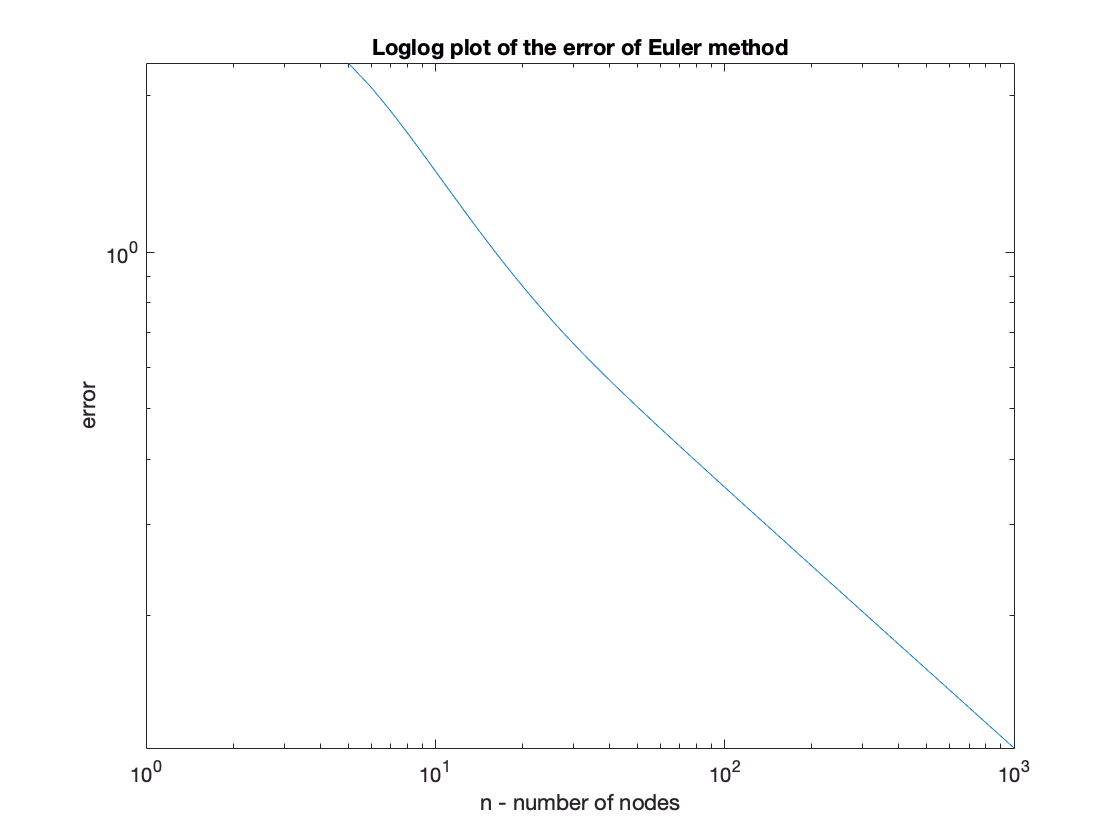

%% euler error for linear system
euler_lin_err = ode_project.err_on_linearSystem_vs_n(A, X0, f_linear, tspan, ns, 'Euler');

## Euler method on the non linear system

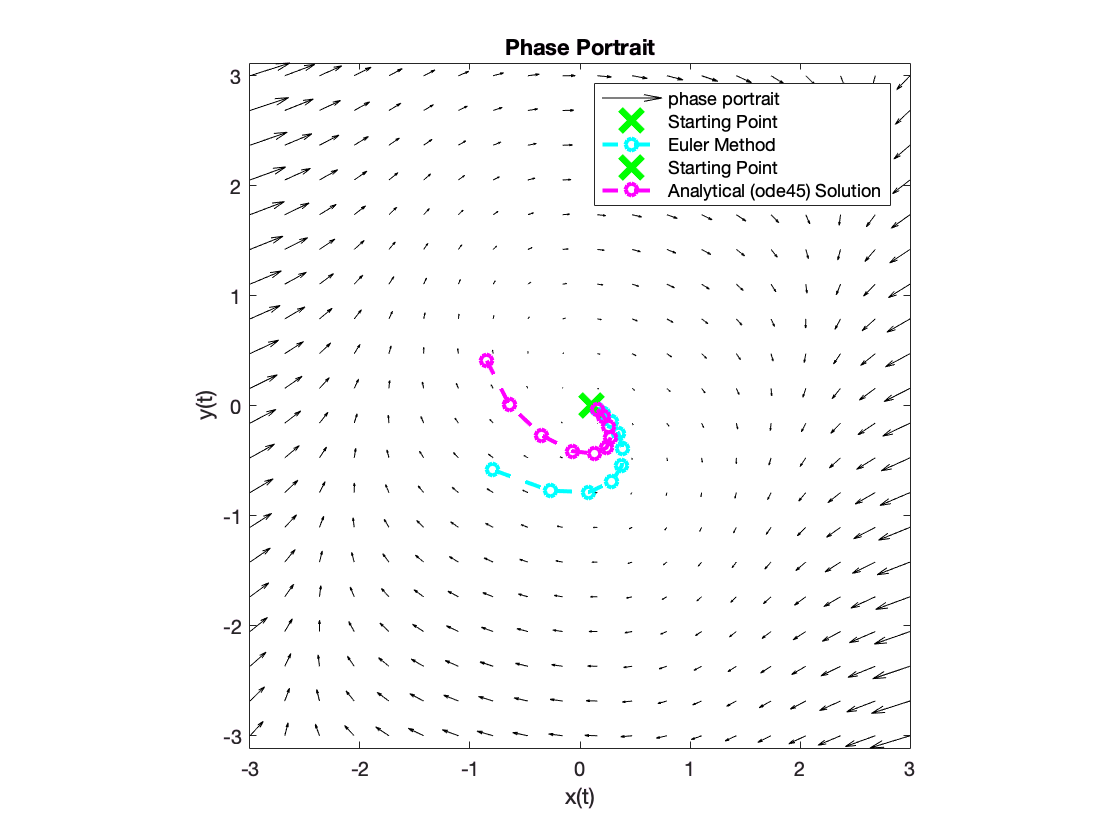


[~, n_euler_sol] = ode_project.Euler_ode(f_nonlinear, X0, tspan, n);
ode_project.portrait_plot(f_nonlinear, 3)
ode_project.plot_solution(n_euler_sol, 'c--o', 'Euler Method')
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Euler Method', 'Starting Point','Analytical (ode45) Solution')

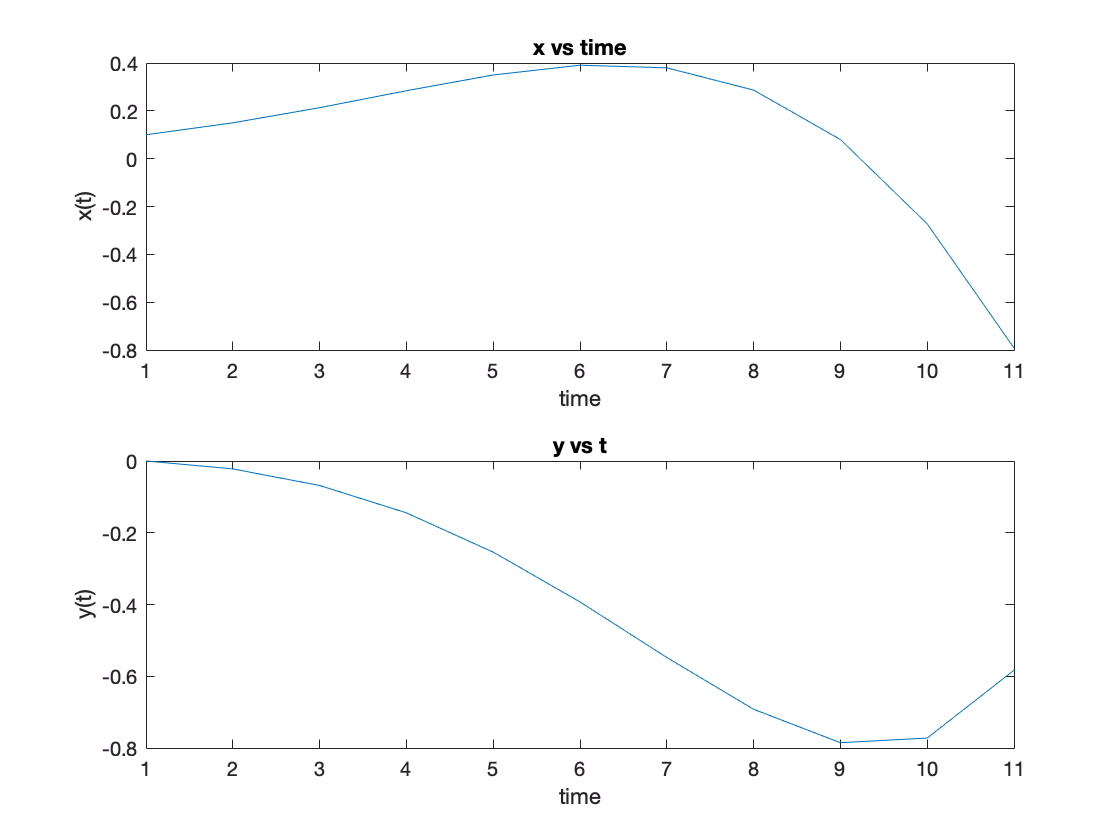

ode_project.plot_xy(n_euler_sol)

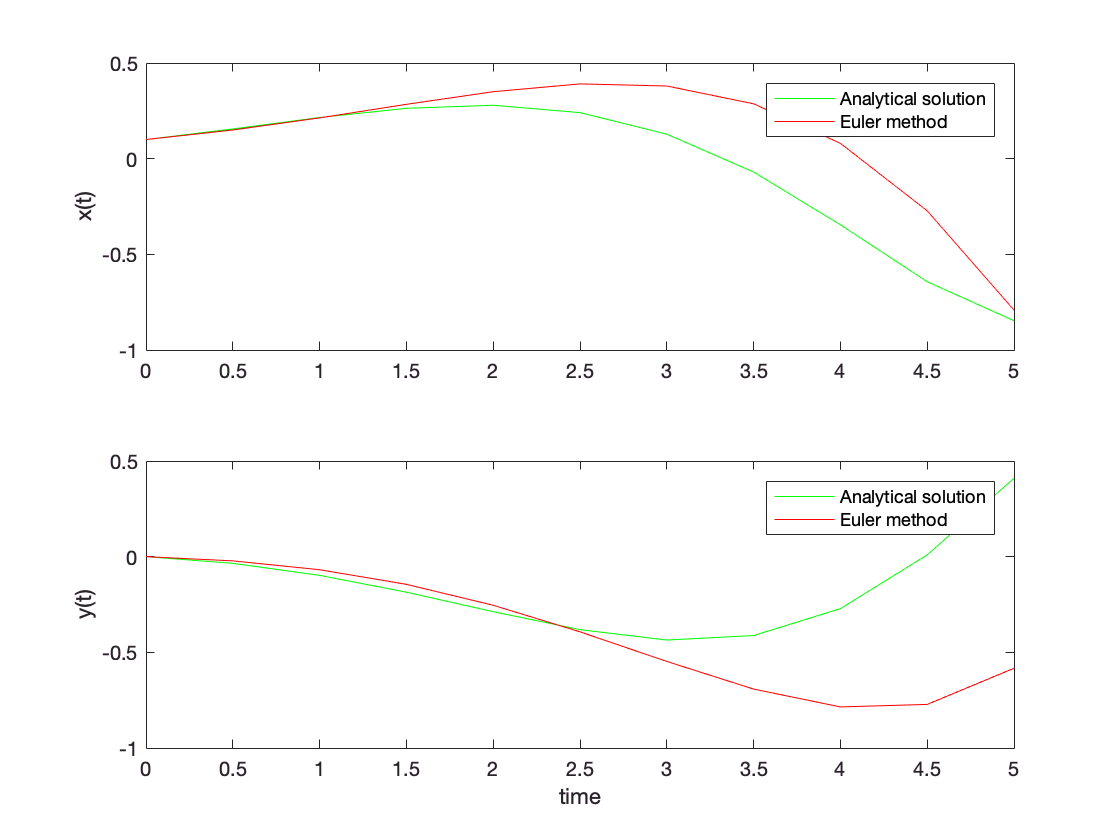


ode_project.plot_comparison(analytical_nlinear_res', n_euler_sol, tspan, n, 'Euler method')

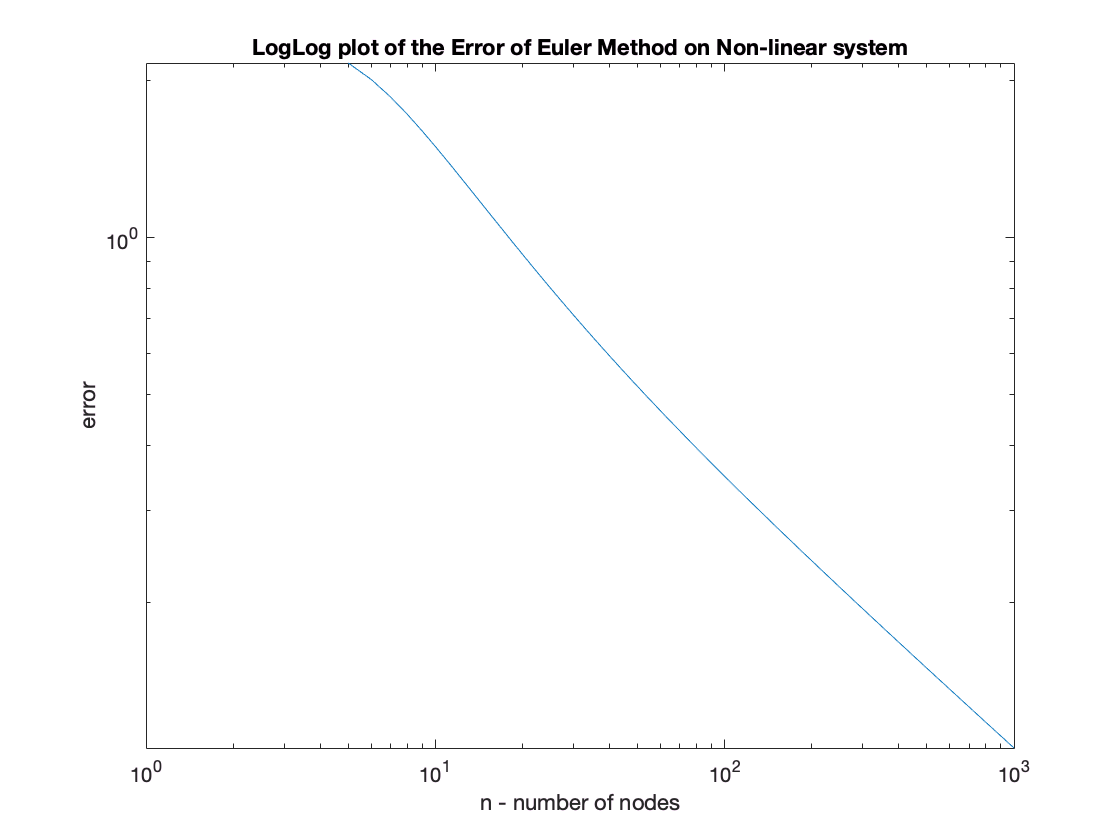


%%% Error Euler on the nonlinear system
euler_nlin_err = ode_project.err_nonlinearSystem_vs_n(f_nonlinear, X0, tspan, ns, 'Euler');

## Runge Kutta methods 

## Runge-Kutta 2nd Order

## linear system

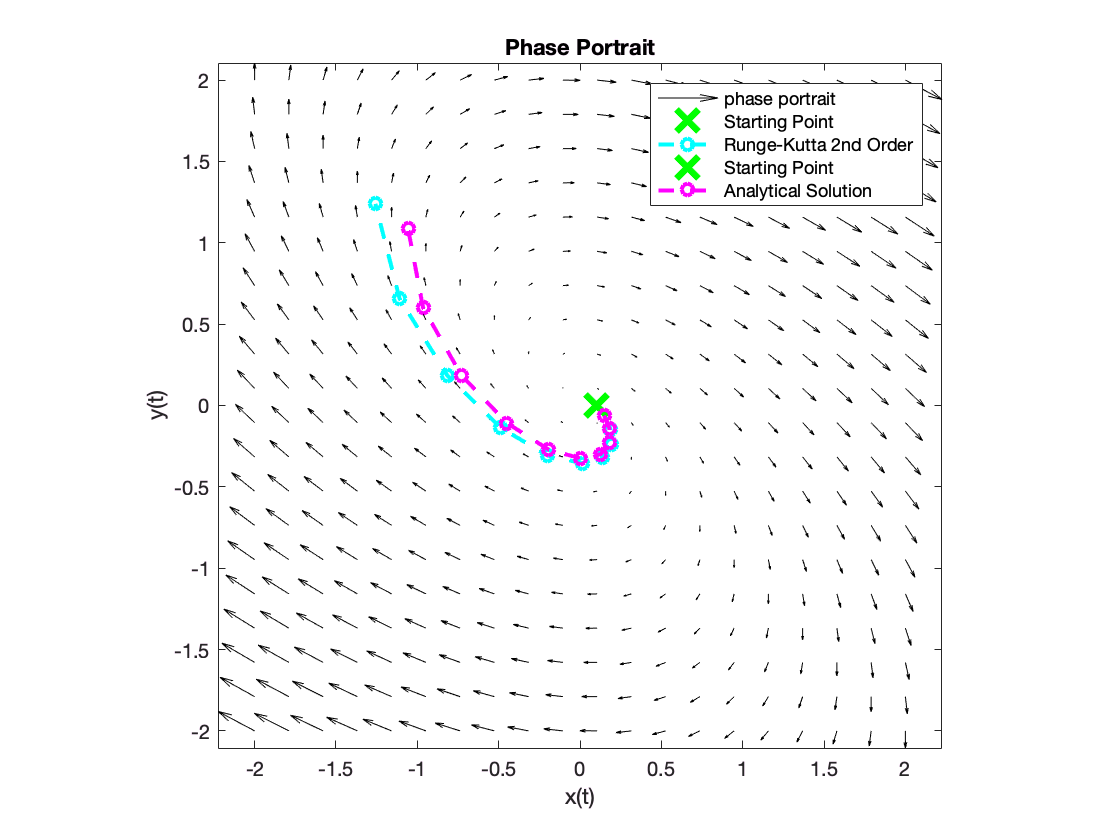


[~, runge2_linear]=ode_project.RK2(f_linear, tspan, X0, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(runge2_linear, 'c--o', 'Runge-Kutta 2nd')
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Runge-Kutta 2nd Order', 'Starting Point','Analytical Solution')

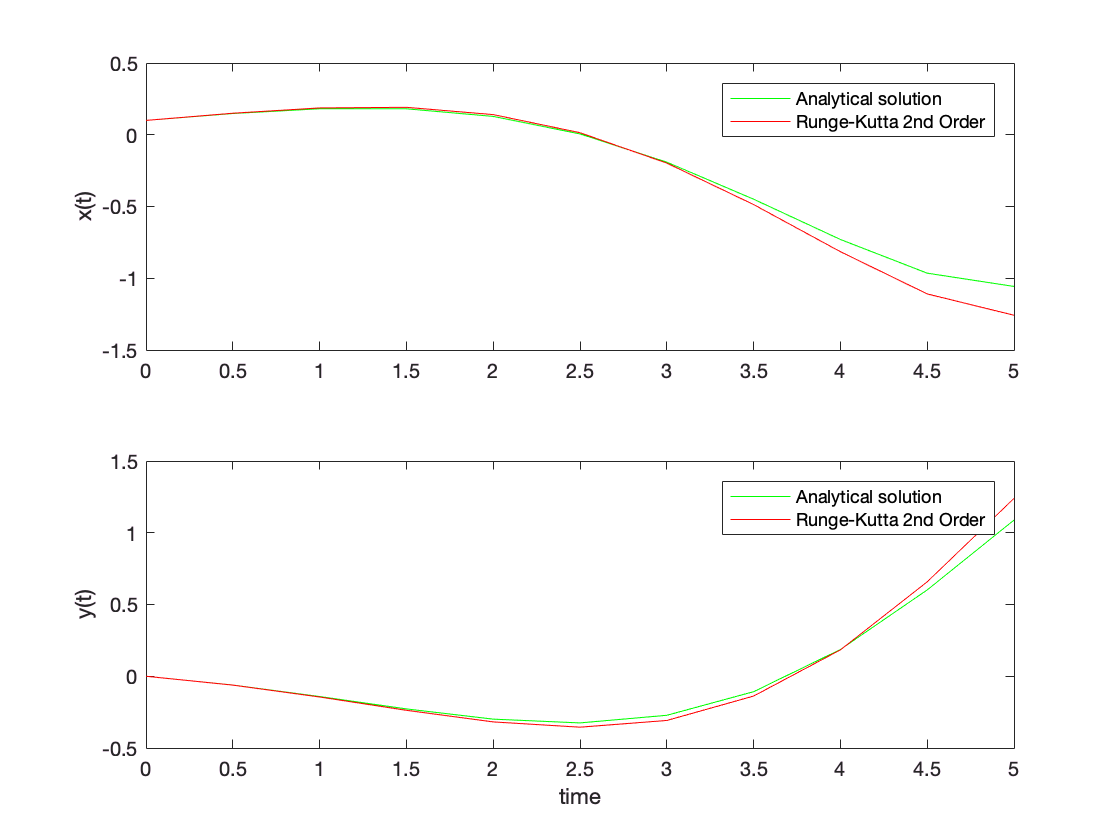


% ode_project.plot_xy(runge_linear)
ode_project.plot_comparison(analytical_sol, runge2_linear, tspan, n, 'Runge-Kutta 2nd Order')

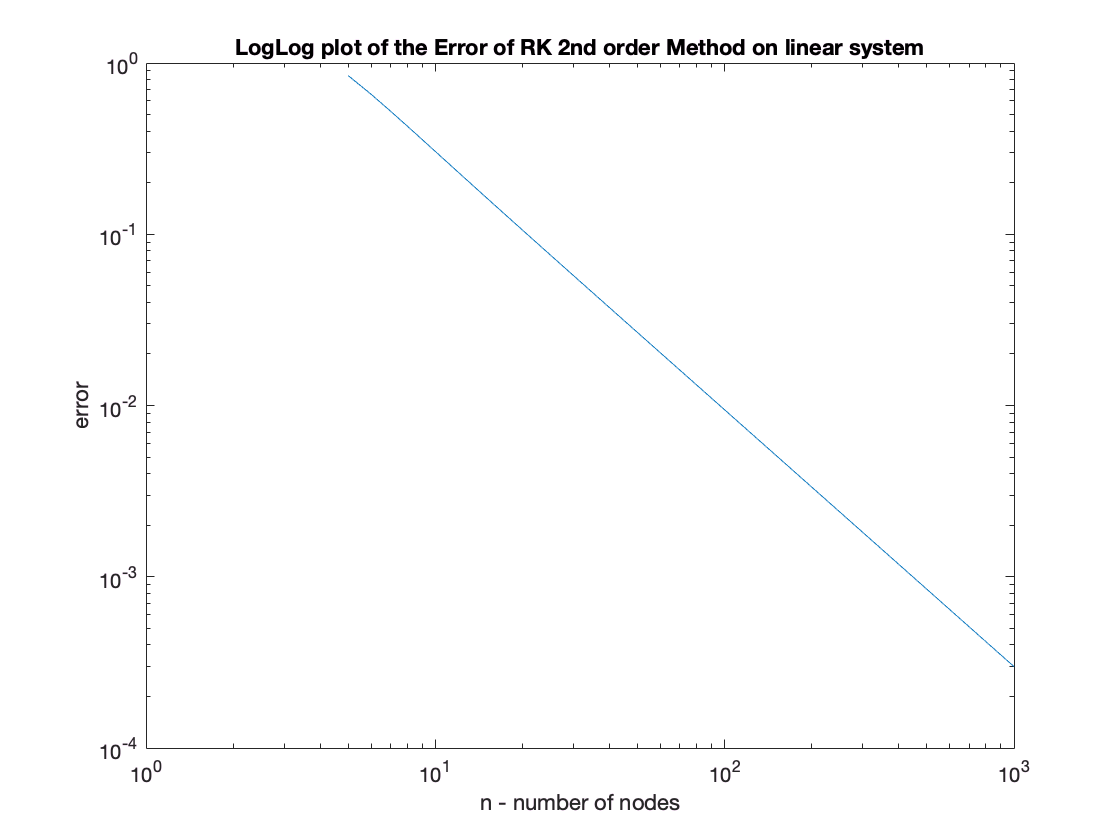

%% RK2 error on Linear System
rk2_lin_err = ode_project.err_on_linearSystem_vs_n(A, X0, f_linear, tspan, ns, 'RK2');

## RK2 on the nonlinear system

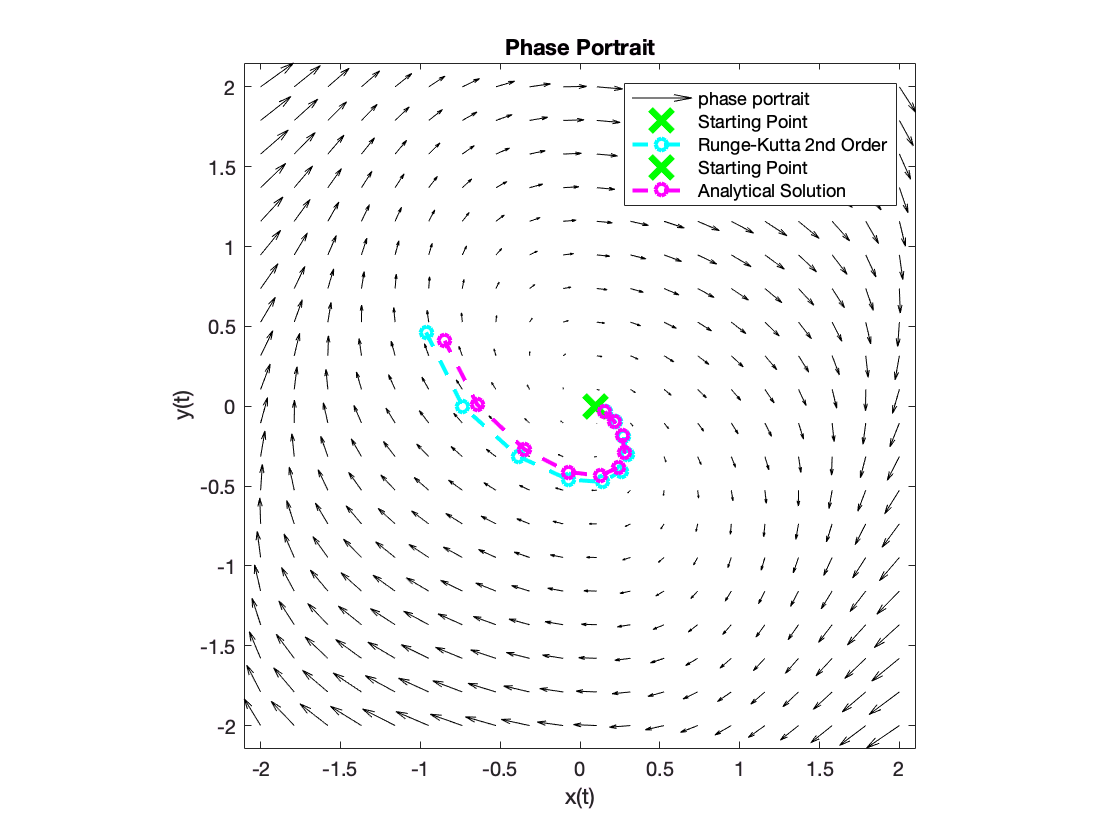


[~, runge2_nlinear]=ode_project.RK2(f_nonlinear, tspan, X0, n);
ode_project.portrait_plot(f_nonlinear, 2)
ode_project.plot_solution(runge2_nlinear, 'c--o', 'Runge-Kutta 2nd Order')
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Runge-Kutta 2nd Order', 'Starting Point','Analytical Solution')

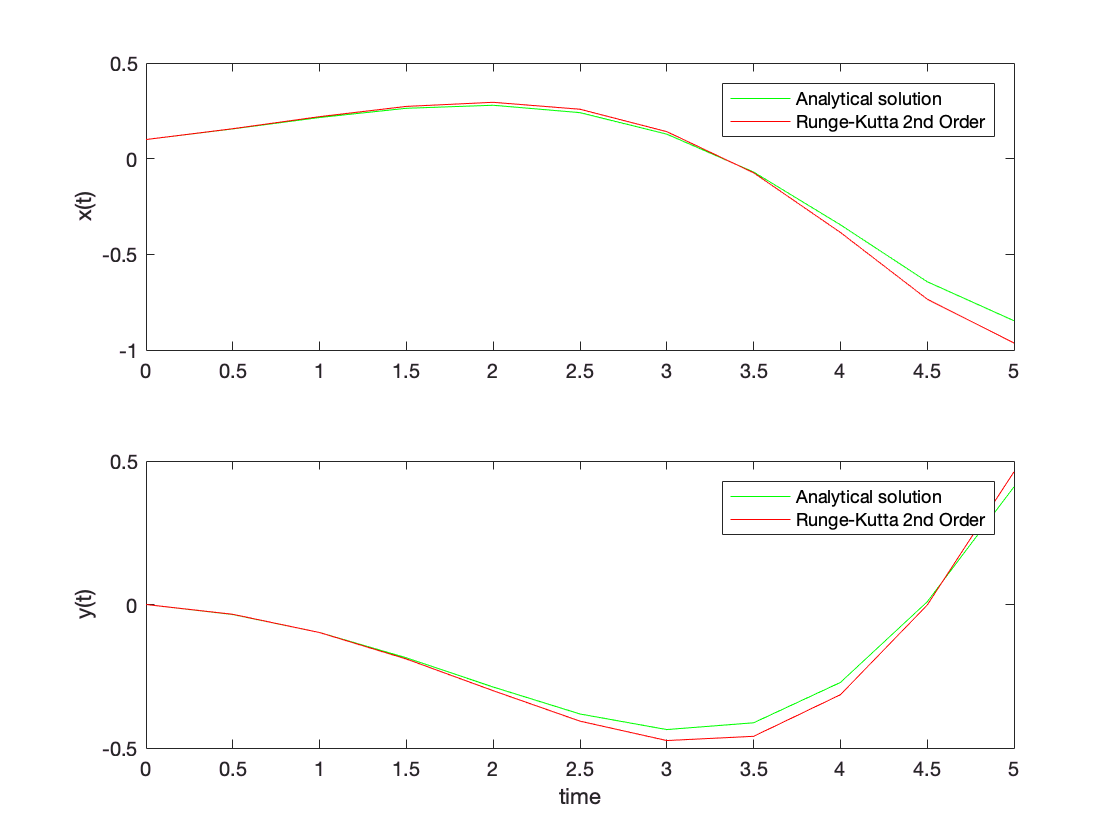

ode_project.plot_comparison(analytical_nlinear_res', runge2_nlinear, tspan, n, 'Runge-Kutta 2nd Order')

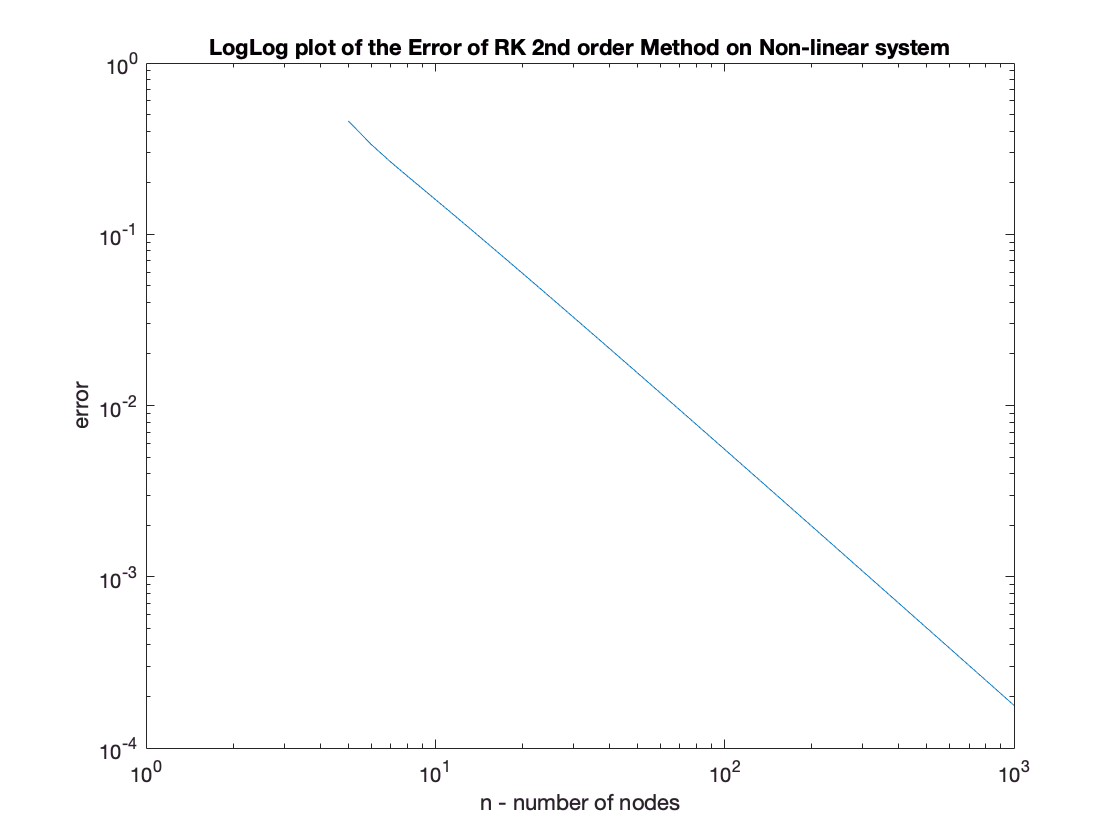


%% RK2 error on the nonlinear system 
rk2_nlin_err = ode_project.err_nonlinearSystem_vs_n(f_nonlinear, X0, tspan, ns, 'RK2');

## Runge-Kutta 4th Order

## linear system

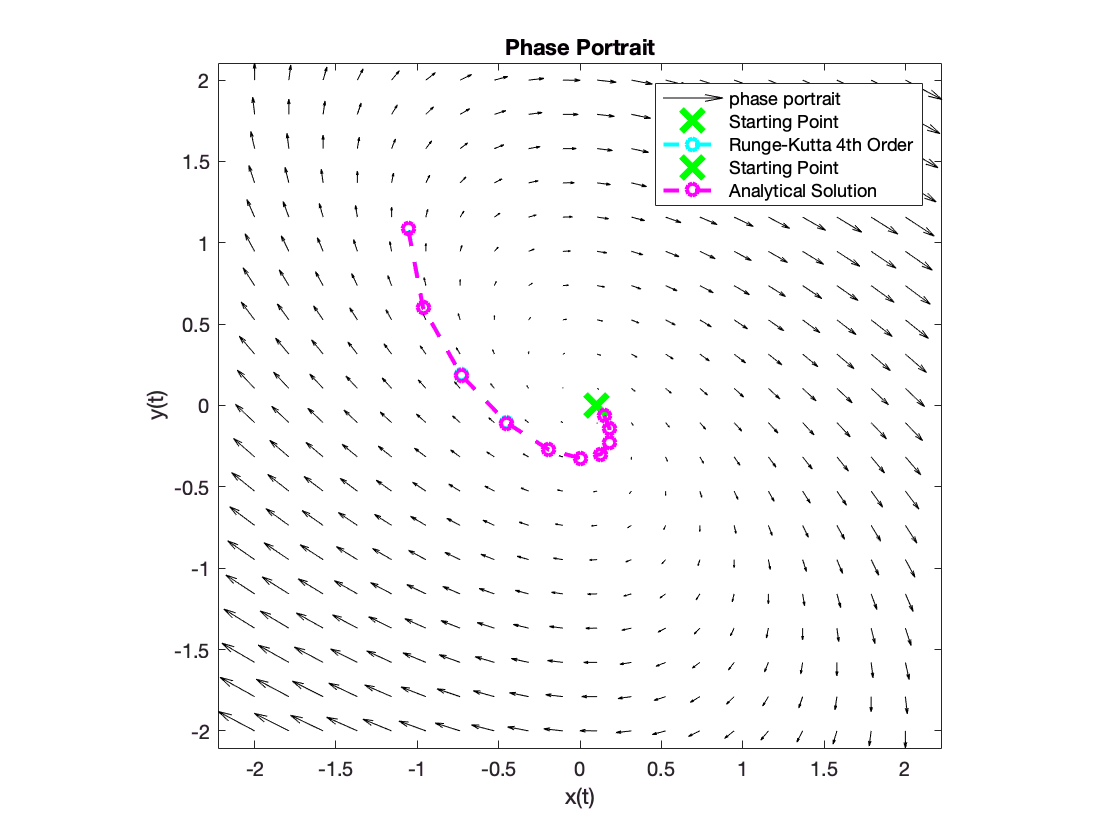


[~, runge4_linear]=ode_project.RK4(f_linear, tspan, X0, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(runge4_linear, 'c--o', 'Runge-Kutta 4th Order')
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Runge-Kutta 4th Order', 'Starting Point','Analytical Solution')

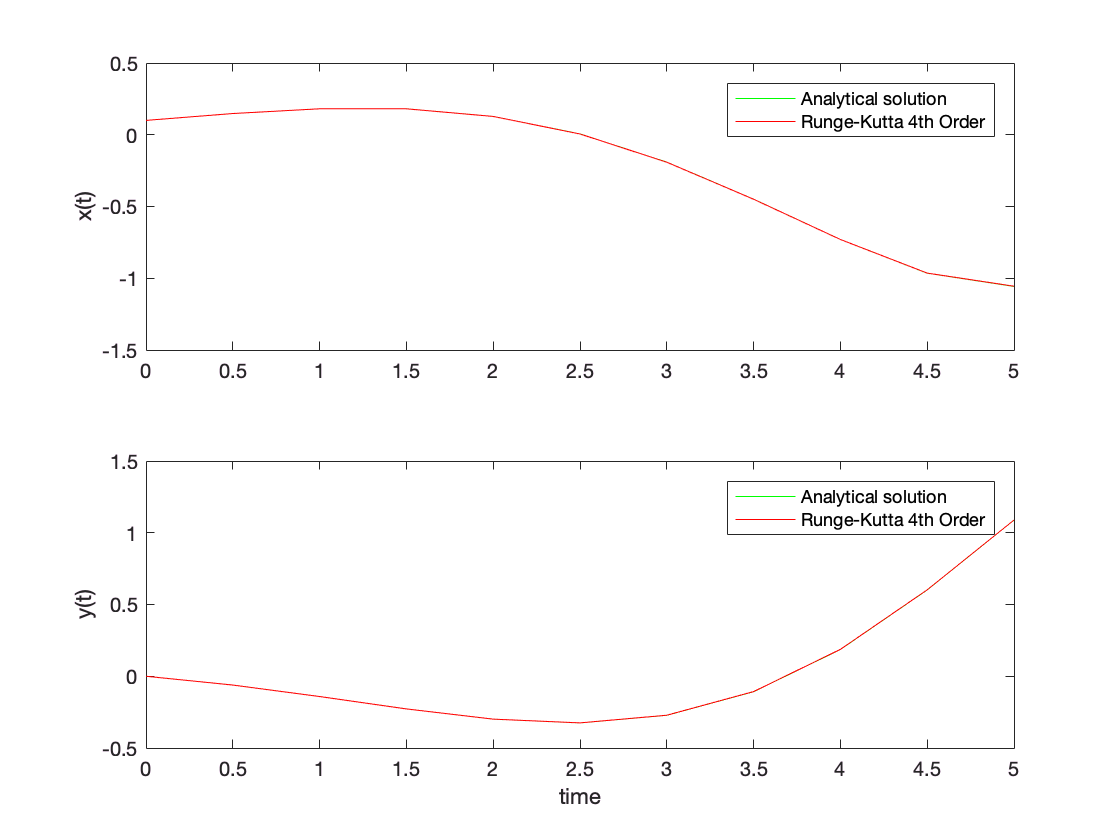


% ode_project.plot_xy(runge4_linear)
ode_project.plot_comparison(analytical_sol, runge4_linear, tspan, n, 'Runge-Kutta 4th Order')

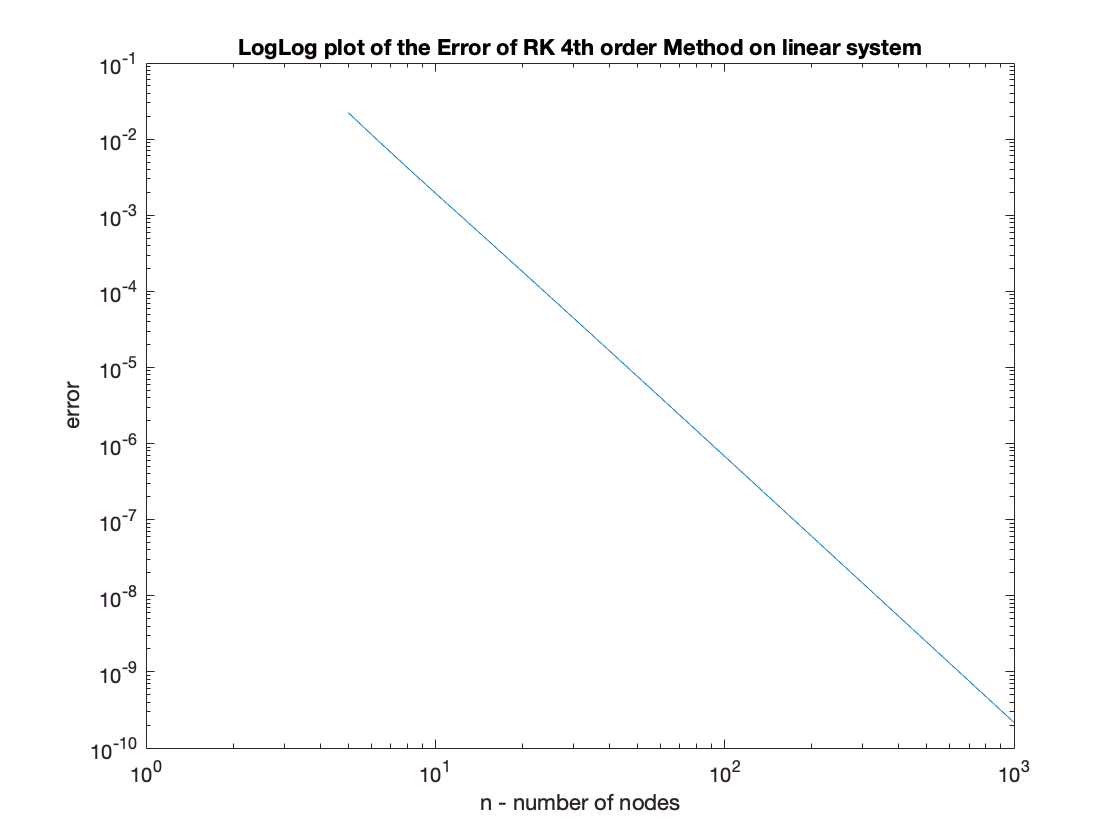

%% RK4 error on the linear system
rk4_lin_err = ode_project.err_on_linearSystem_vs_n(A, X0, f_linear, tspan, ns, 'RK4');

## Non linear system - RK4

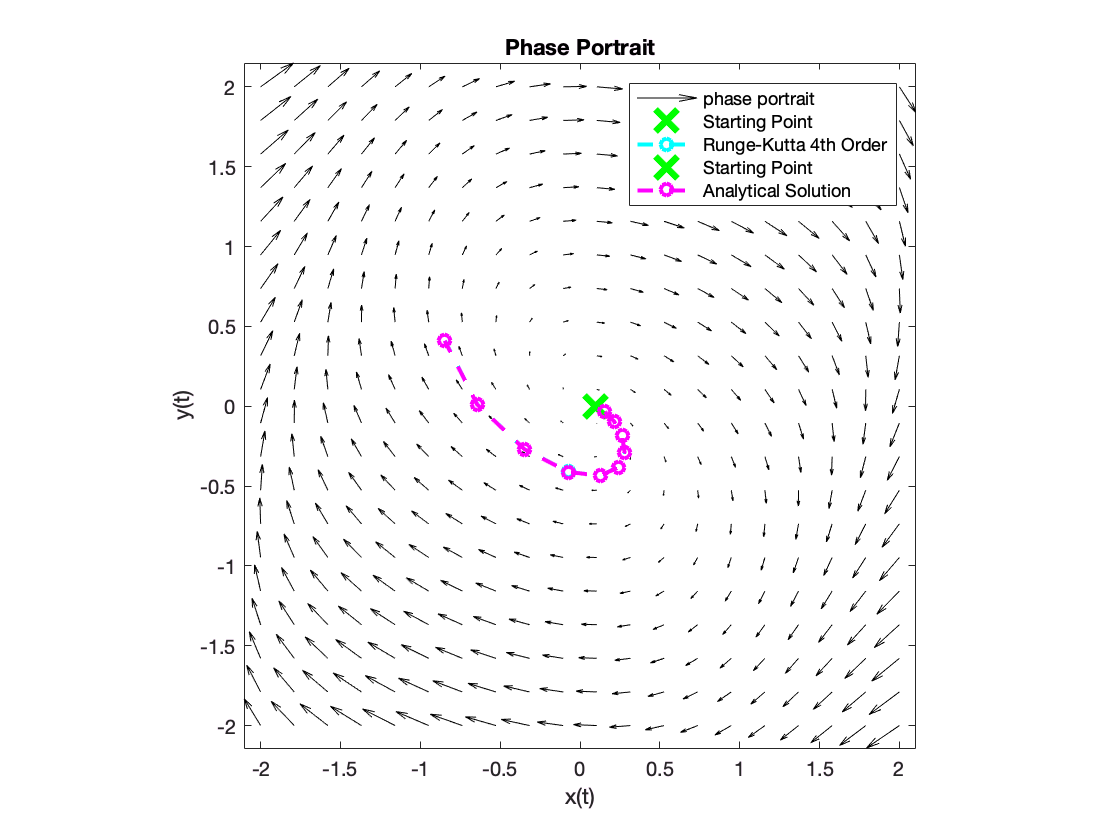


[~, runge4_nlinear]=ode_project.RK4(f_nonlinear, tspan, X0, n);
ode_project.portrait_plot(f_nonlinear, 2)
ode_project.plot_solution(runge4_nlinear, 'c--o', 'Runge-Kutta 4th Order')
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Runge-Kutta 4th Order', 'Starting Point','Analytical Solution')

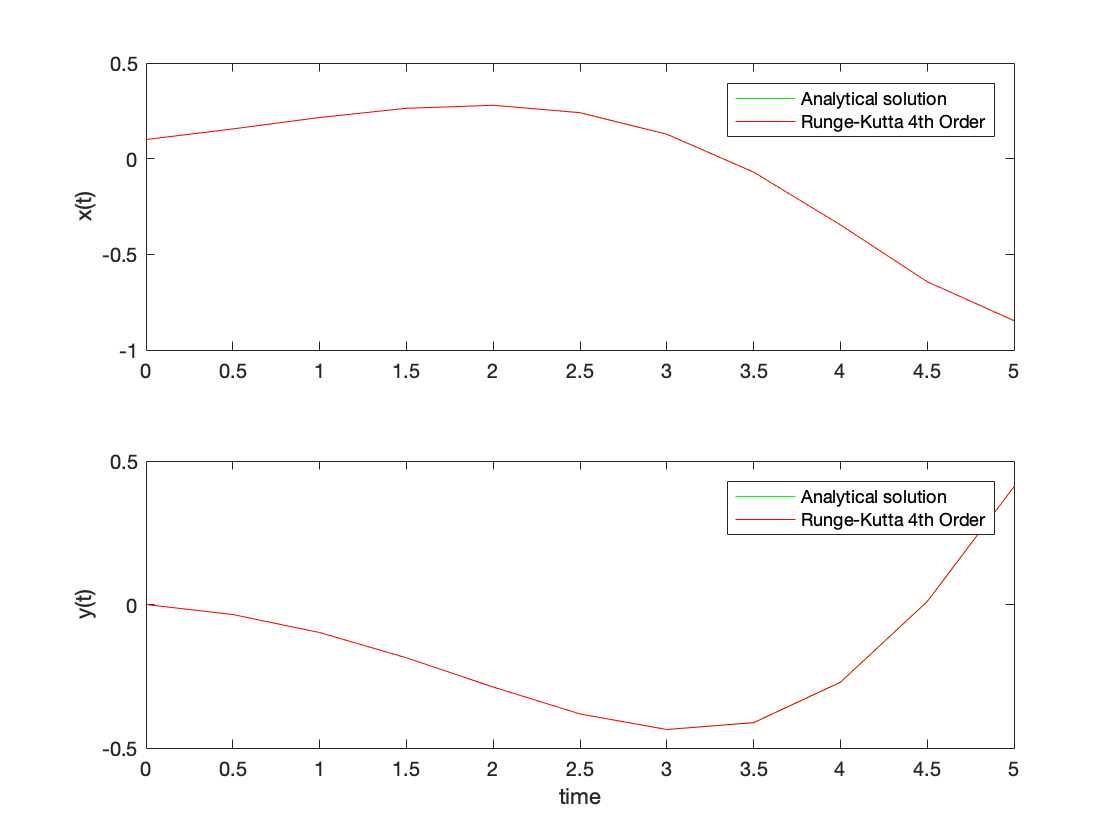

ode_project.plot_comparison(analytical_nlinear_res', runge4_nlinear, tspan, n, 'Runge-Kutta 4th Order')

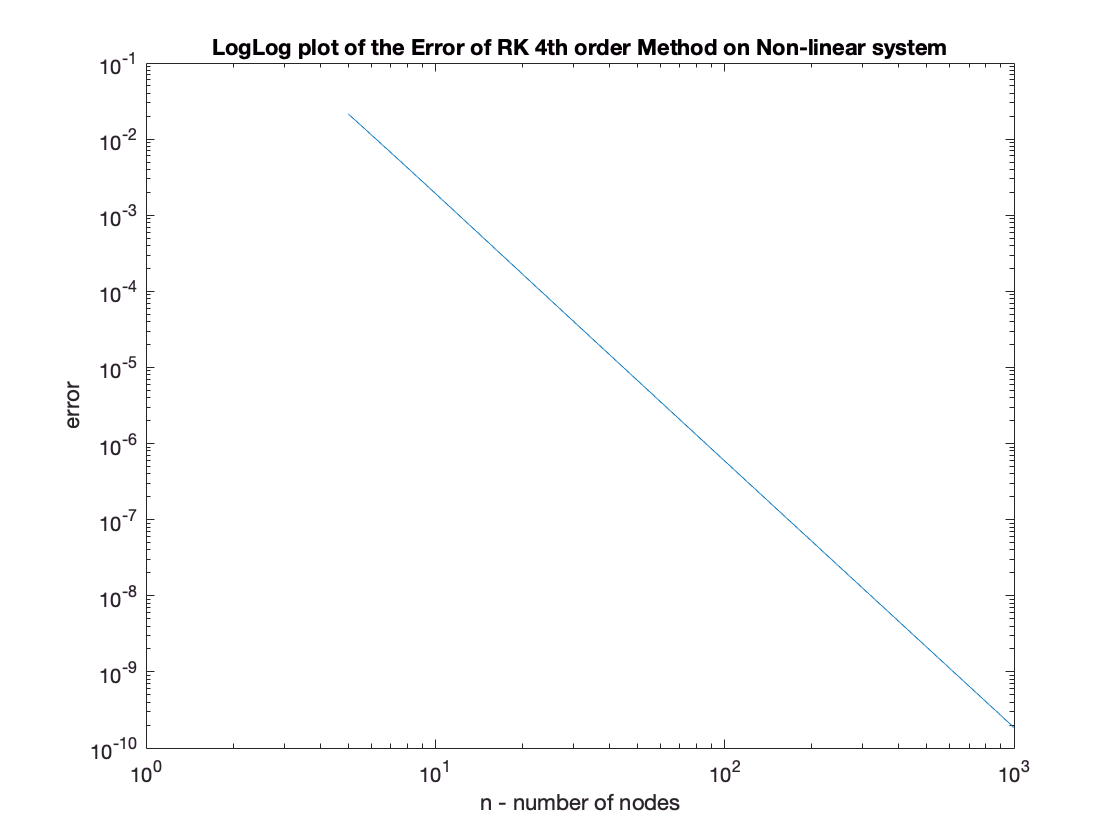


%% RK4 error on non linear system
rk4_nlin_err = ode_project.err_nonlinearSystem_vs_n(f_nonlinear, X0, tspan, ns, 'RK4');

## Multi-step Methods

## Adam Bashforth 2nd order

## linear system

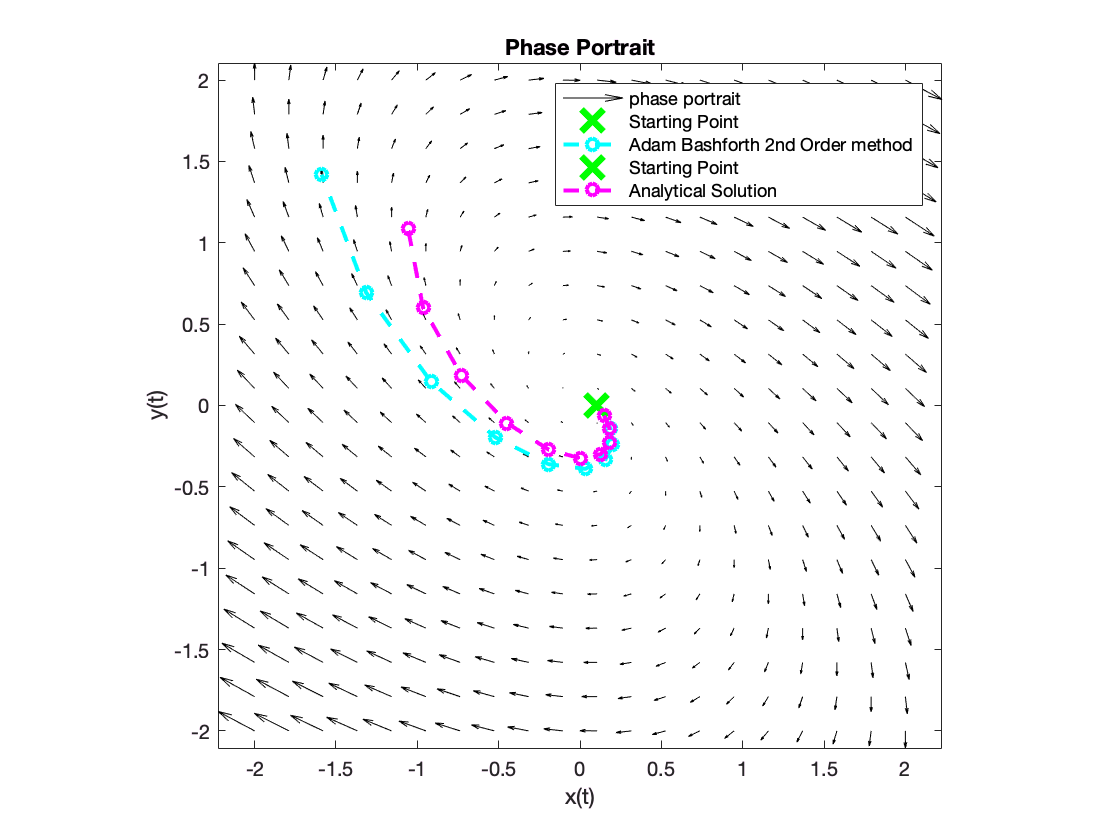


[~, ab2_linear]=ode_project.adam_bashforth2(f_linear, tspan, X0, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(ab2_linear, 'c--o', 'Adam Bashforth 2nd Order method')
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Adam Bashforth 2nd Order method', 'Starting Point','Analytical Solution')

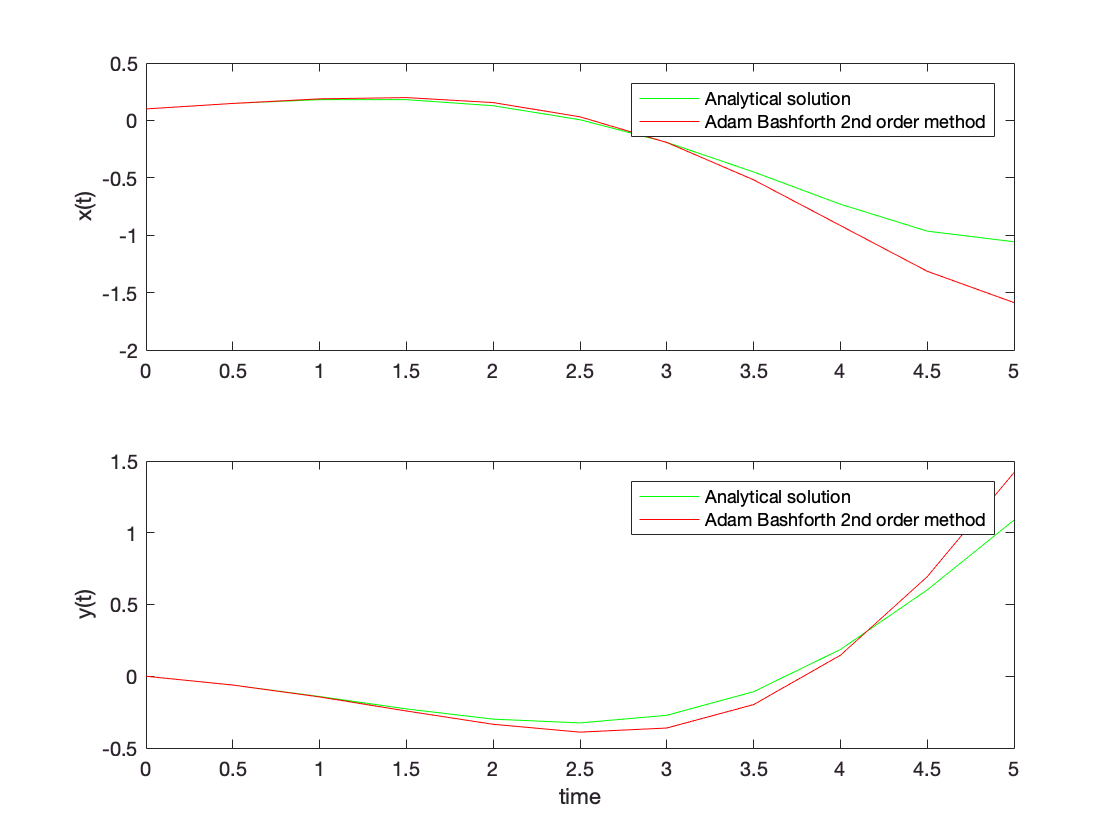


ode_project.plot_comparison(analytical_sol, ab2_linear, tspan, n, 'Adam Bashforth 2nd order method')

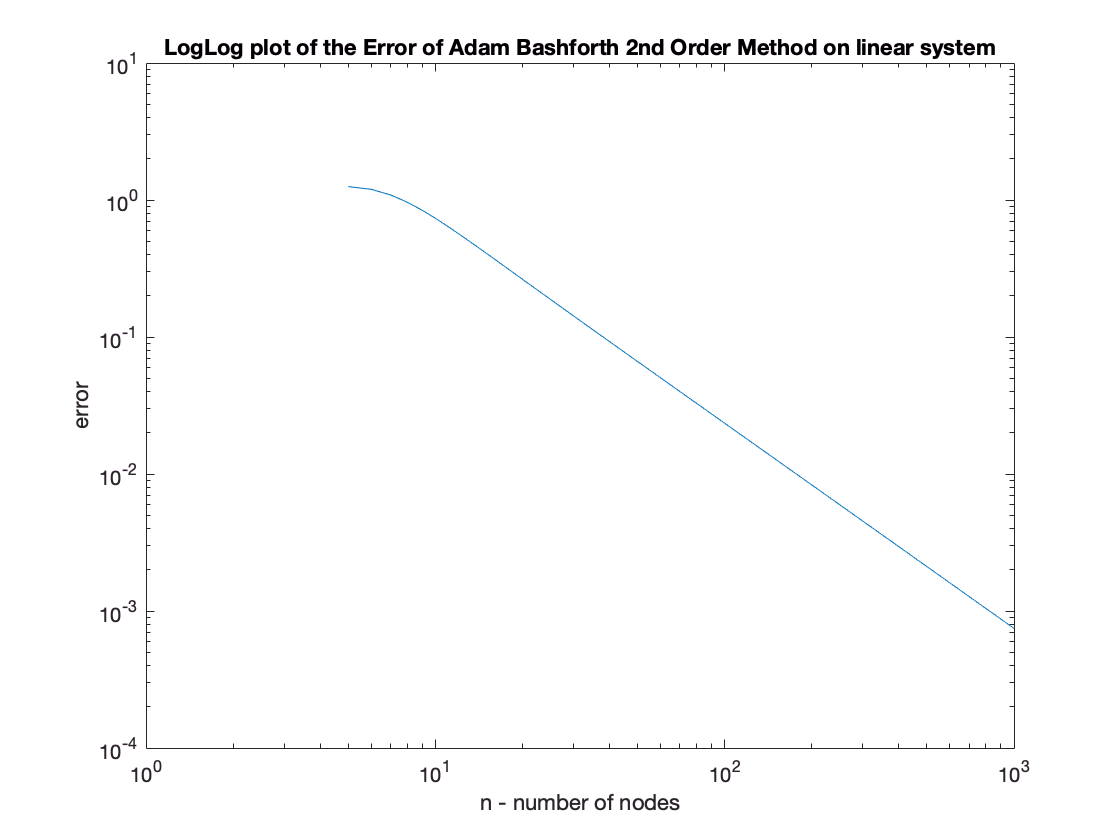

%% AB2 error on linear system
ab2_lin_err = ode_project.err_on_linearSystem_vs_n(A, X0, f_linear, tspan, ns, 'ab2');

## non linear system

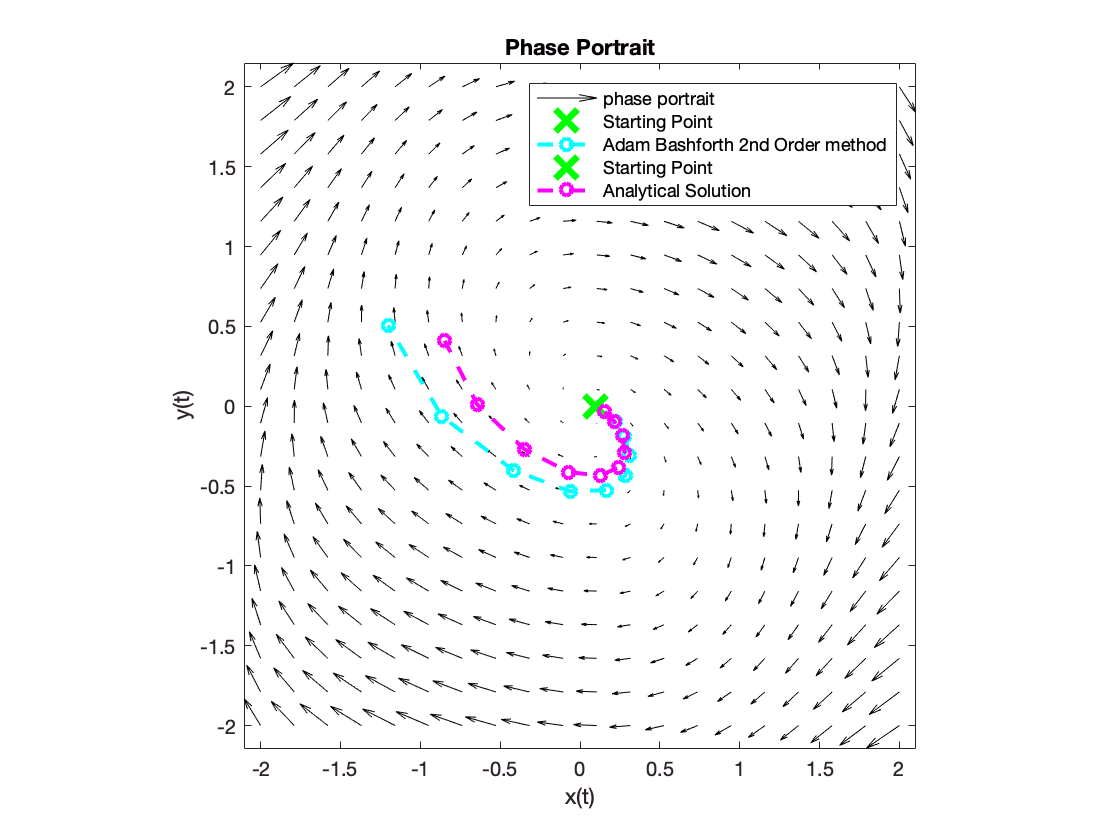


[~, ab2_nlinear]=ode_project.adam_bashforth2(f_nonlinear, tspan, X0, n);
ode_project.portrait_plot(f_nonlinear, 2)
ode_project.plot_solution(ab2_nlinear, 'c--o', 'Adam Bashforth 2nd Order method')
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Adam Bashforth 2nd Order method', 'Starting Point','Analytical Solution')

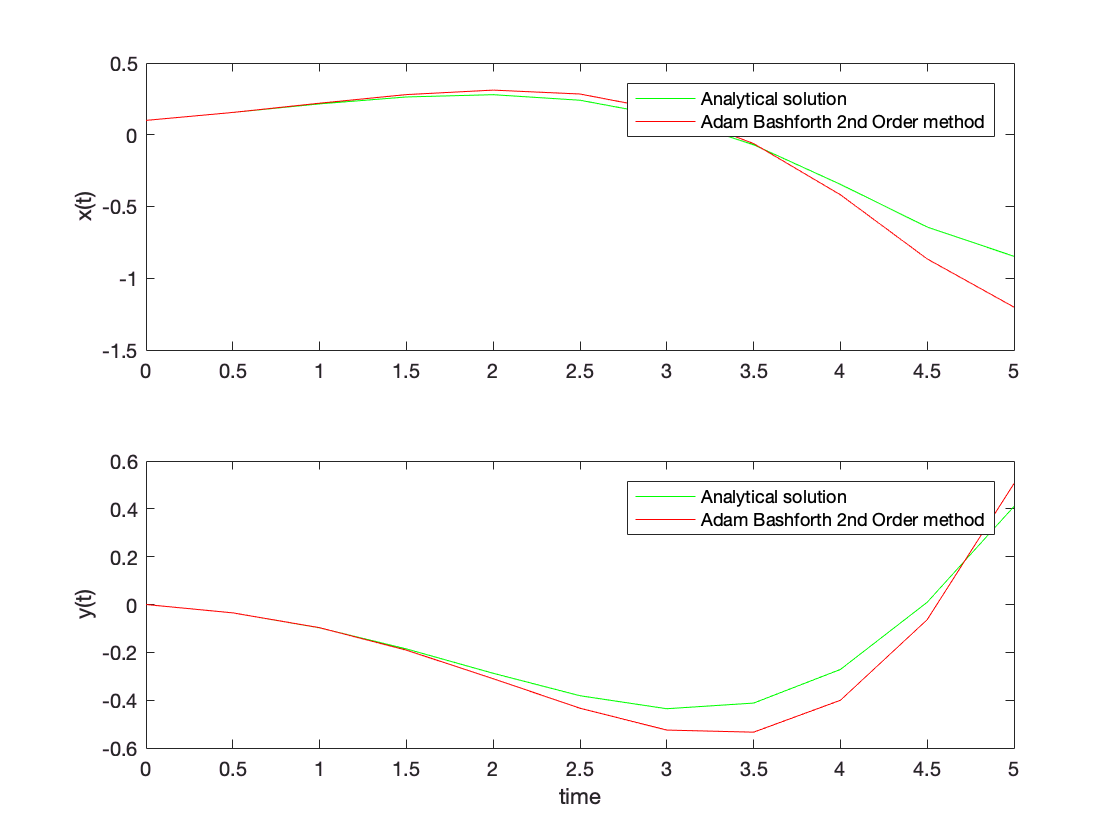


ode_project.plot_comparison(analytical_nlinear_res', ab2_nlinear, tspan, n, 'Adam Bashforth 2nd Order method')

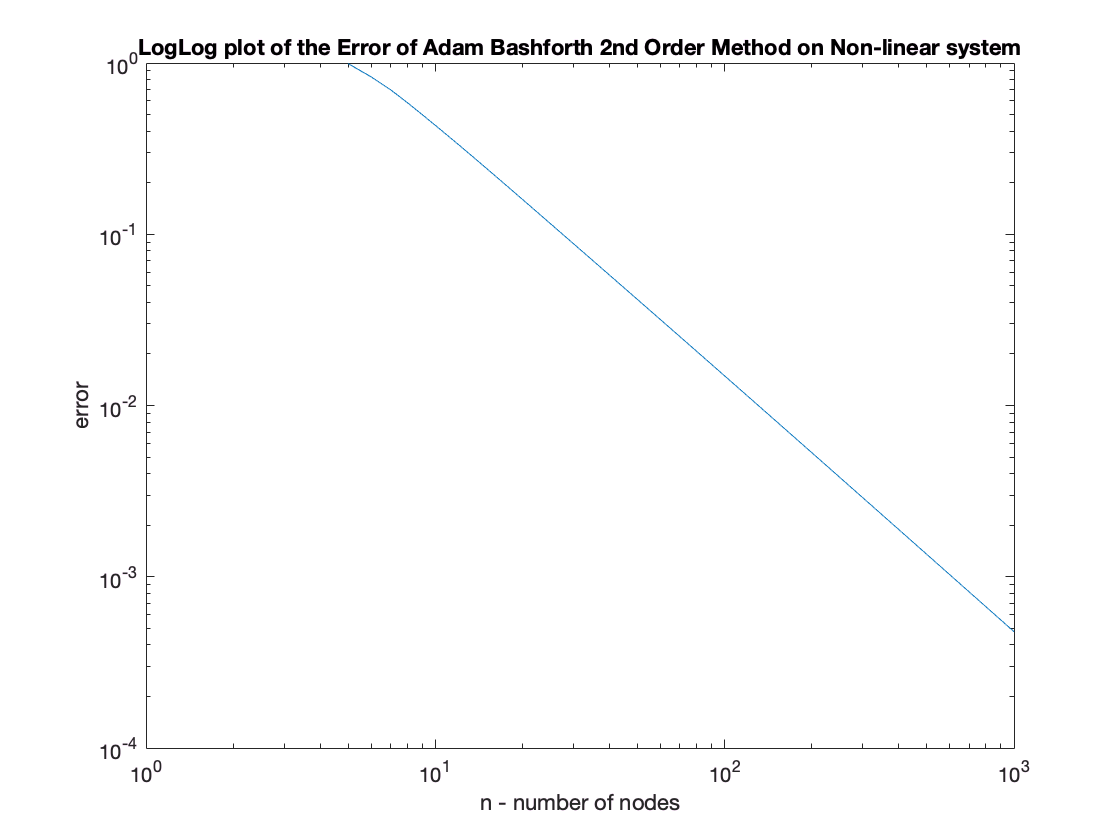

%% AB2 error on the nonlinear system
ab2_nlin_err = ode_project.err_nonlinearSystem_vs_n(f_nonlinear, X0, tspan, ns, 'ab2');

## Adam Bashforth 4th order

## linear system

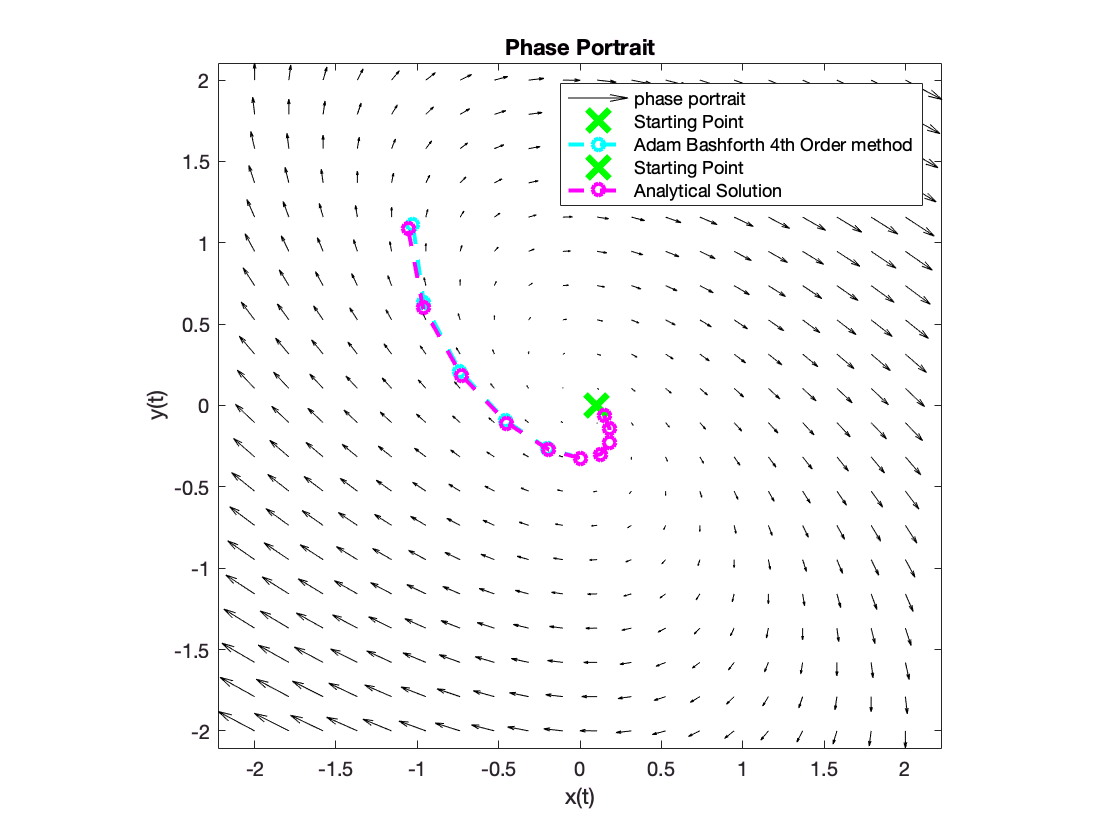


[~, ab4_linear]=ode_project.adam_bashforth4(f_linear, tspan, X0, n);
ode_project.portrait_plot(f_linear, 2)
ode_project.plot_solution(ab4_linear, 'c--o', 'Adam Bashforth 4th Order method')
ode_project.plot_solution(analytical_sol, 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Adam Bashforth 4th Order method', 'Starting Point','Analytical Solution')

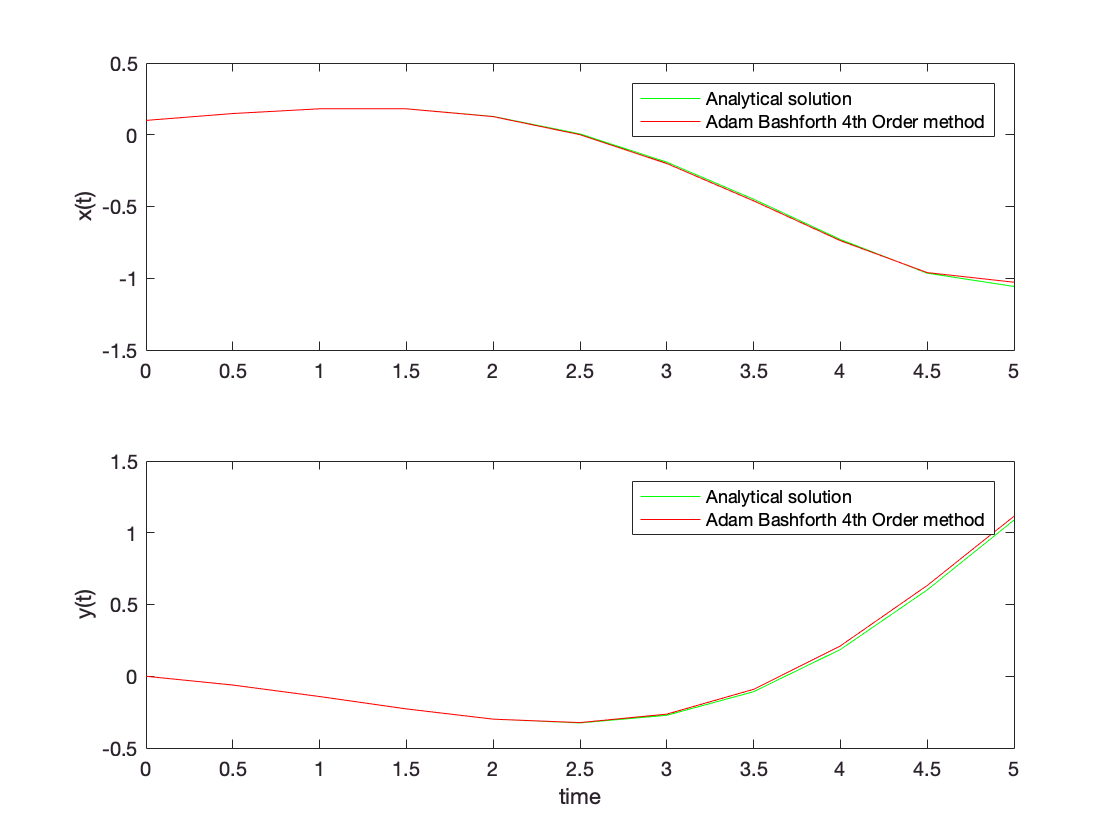


ode_project.plot_comparison(analytical_sol, ab4_linear, tspan, n, 'Adam Bashforth 4th Order method')

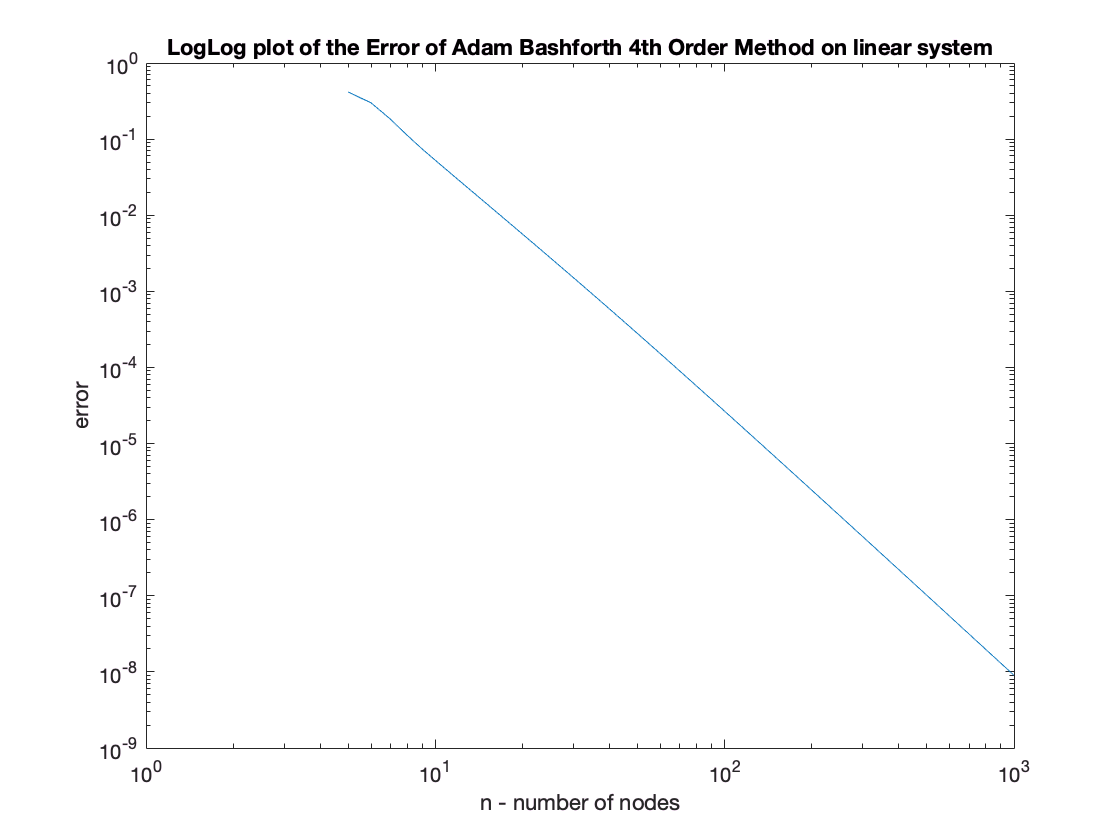


%% AB4 error on the linear system
ab4_lin_err = ode_project.err_on_linearSystem_vs_n(A, X0, f_linear, tspan, ns, 'ab4');

## non-linear system

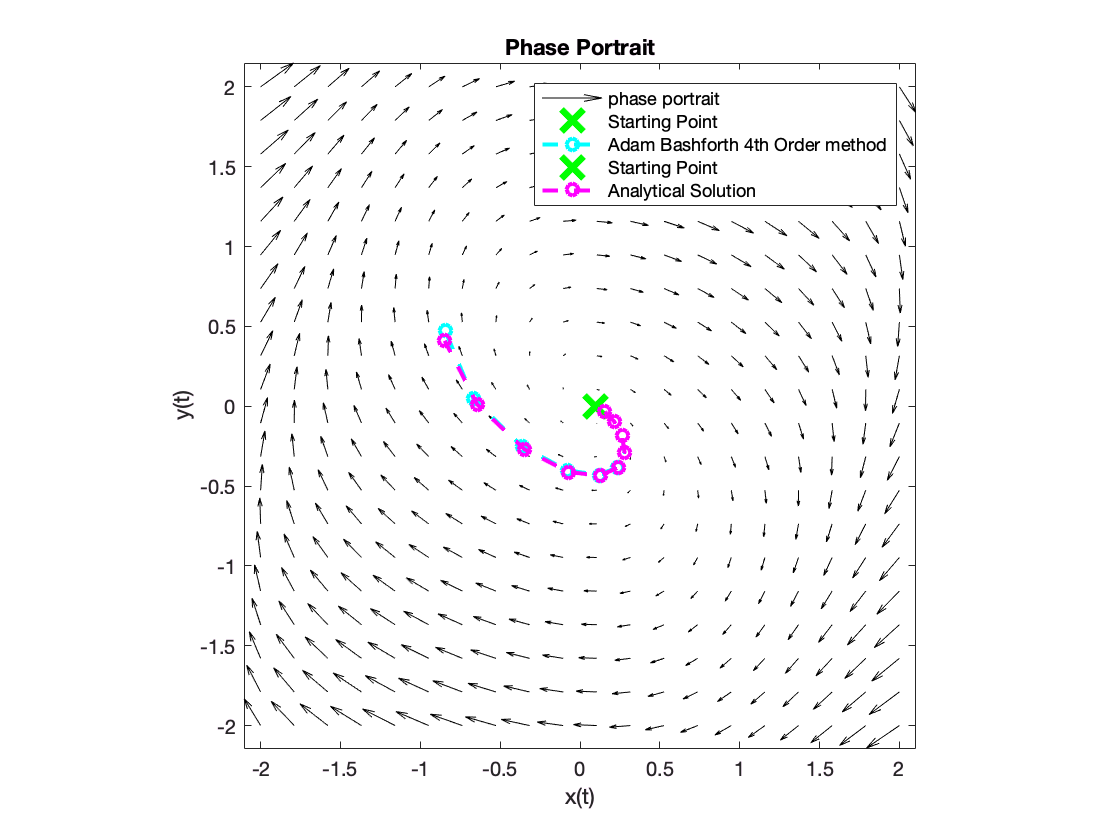


[~, ab4_nlinear]=ode_project.adam_bashforth4(f_nonlinear, tspan, X0, n);
ode_project.portrait_plot(f_nonlinear, 2)
ode_project.plot_solution(ab4_nlinear, 'c--o', 'Adam Bashforth 4th Order method')
ode_project.plot_solution(analytical_nlinear_res', 'm--o', 'Analytical Solution')
legend('phase portrait', 'Starting Point', 'Adam Bashforth 4th Order method', 'Starting Point','Analytical Solution')

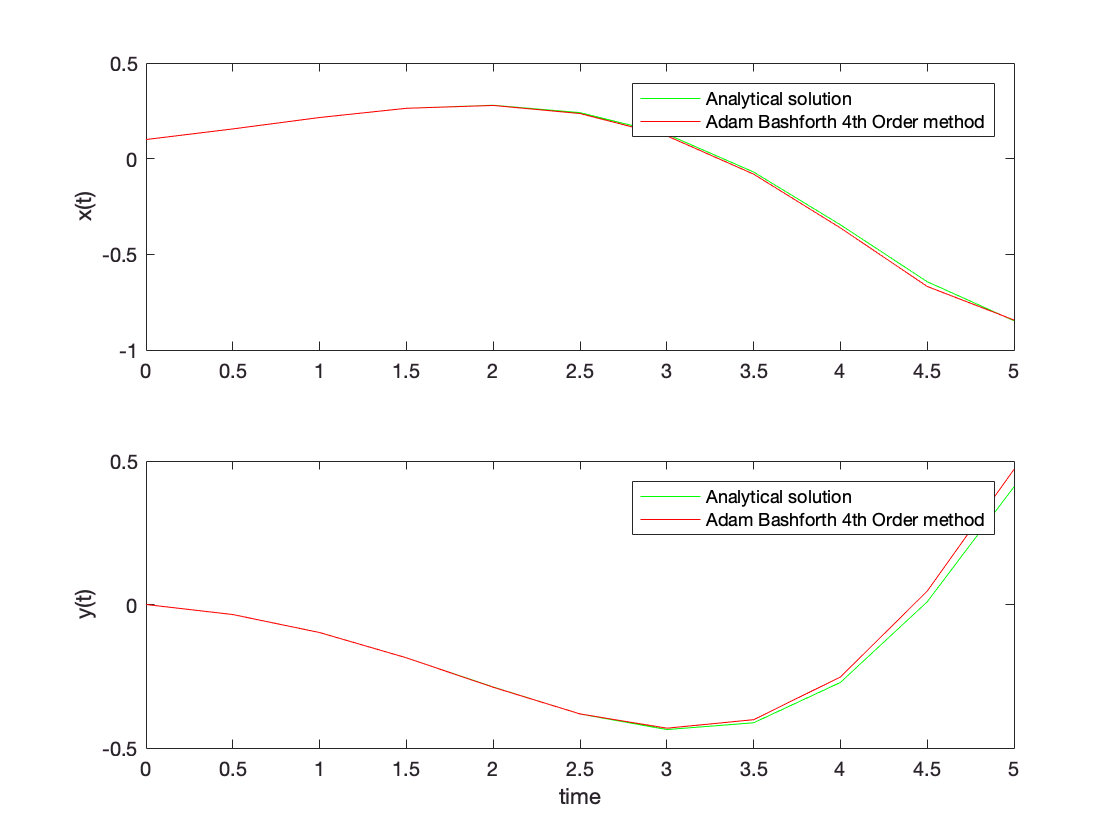


ode_project.plot_comparison(analytical_nlinear_res', ab4_nlinear, tspan, n, 'Adam Bashforth 4th Order method')

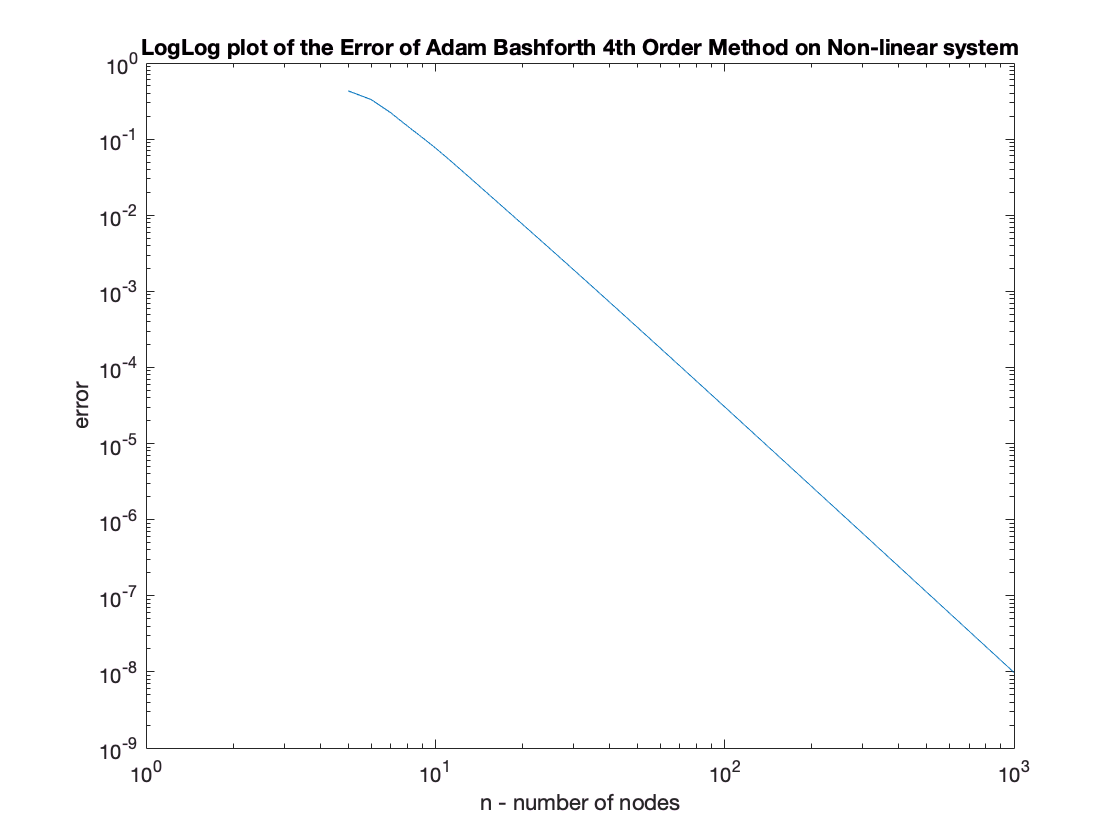

%% AB4 error on the nonlinear system
ab4_nlin_err = ode_project.err_nonlinearSystem_vs_n(f_nonlinear, X0, tspan, ns, 'ab4');

## Comparison of the methods

## linear-system

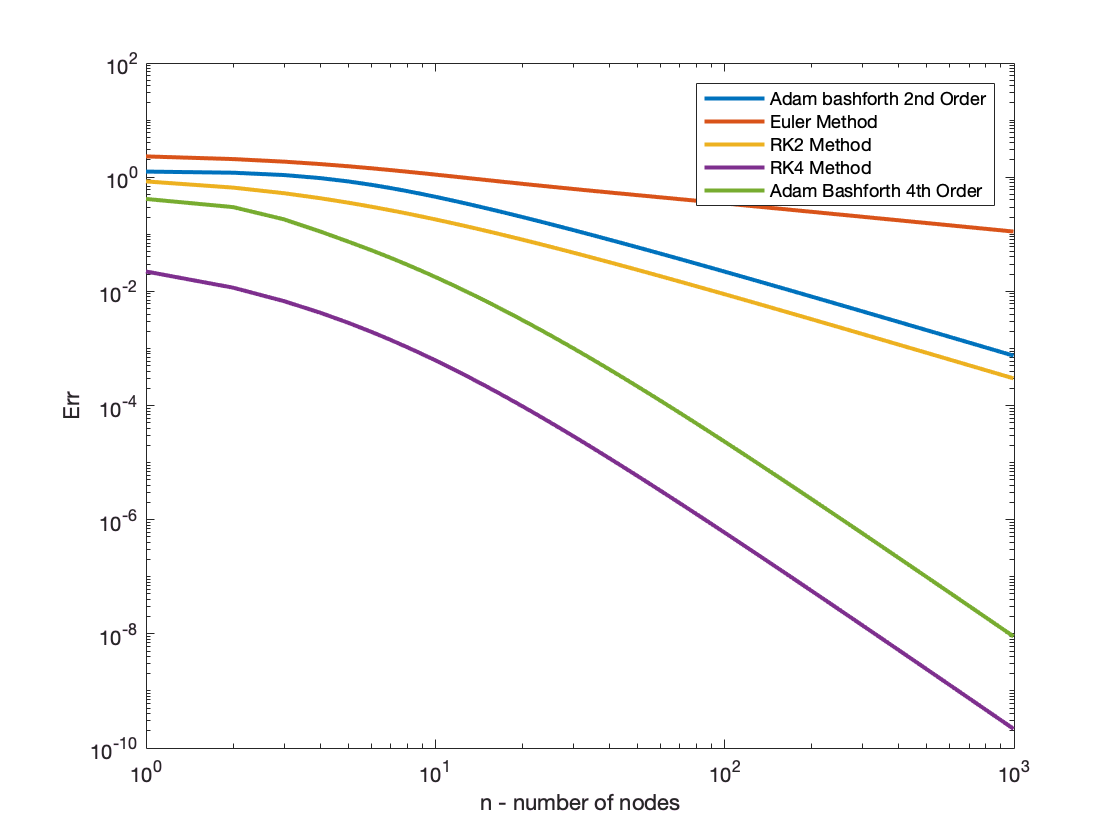


loglog(ab2_lin_err, 'lineWidth', 2, 'DisplayName', 'Adam bashforth 2nd Order');
hold on;
loglog(euler_lin_err, 'lineWidth', 2, 'DisplayName', 'Euler Method')
loglog(rk2_lin_err, 'lineWidth', 2, 'DisplayName', 'RK2 Method')
loglog(rk4_lin_err, 'lineWidth', 2, 'DisplayName', 'RK4 Method')
loglog(ab4_lin_err, 'lineWidth', 2, 'DisplayName', 'Adam Bashforth 4th Order')
legend('show')
ylabel('Err')
xlabel('n - number of nodes')
hold off;

## Nonlinear-system

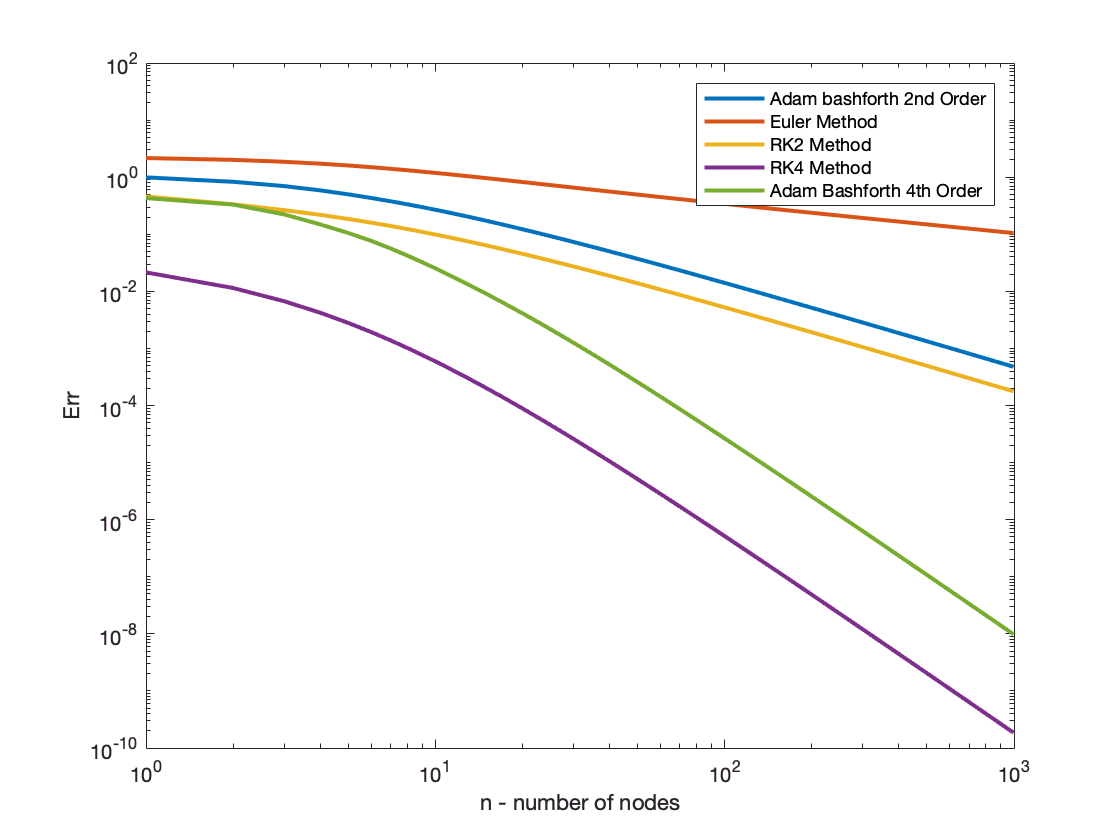


loglog(ab2_nlin_err, 'lineWidth', 2, 'DisplayName', 'Adam bashforth 2nd Order');
hold on;
loglog(euler_nlin_err, 'lineWidth', 2, 'DisplayName', 'Euler Method')
loglog(rk2_nlin_err, 'lineWidth', 2, 'DisplayName', 'RK2 Method')
loglog(rk4_nlin_err, 'lineWidth', 2, 'DisplayName', 'RK4 Method')
loglog(ab4_nlin_err, 'lineWidth', 2, 'DisplayName', 'Adam Bashforth 4th Order')
legend('show')
ylabel('Err')
xlabel('n - number of nodes')
hold off;

## Error with respect to step size

## Linear-system

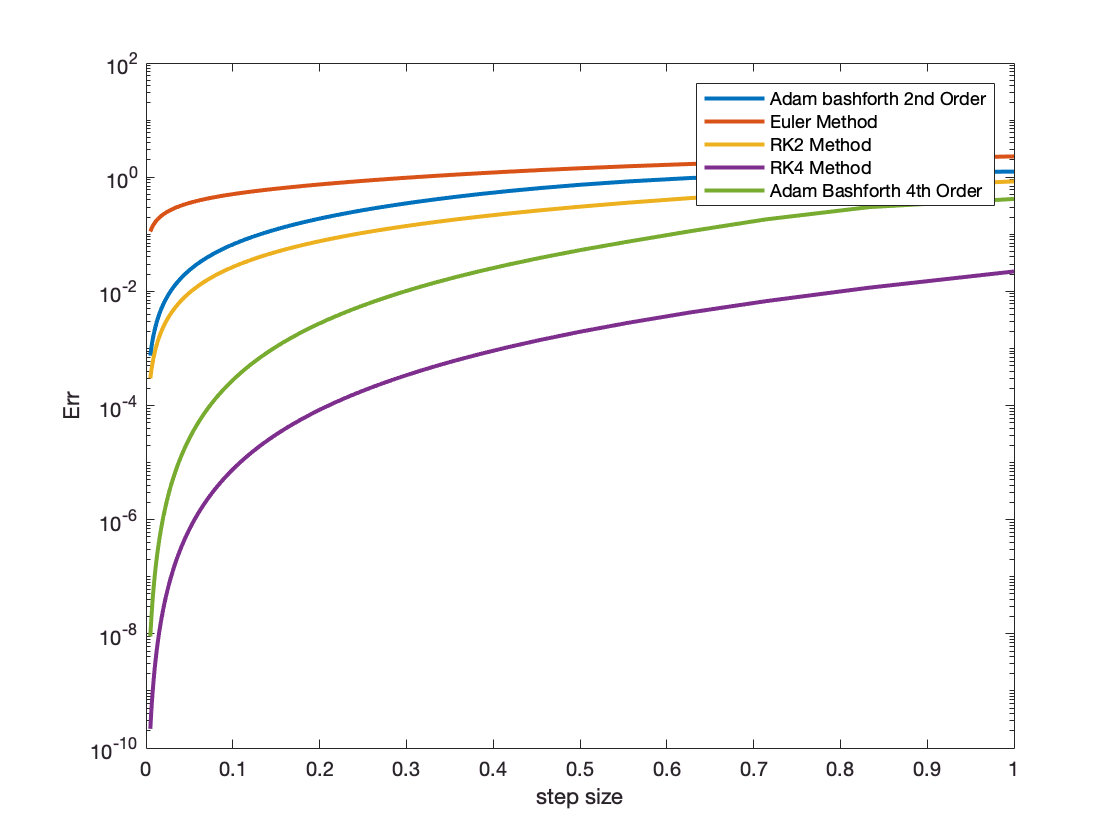


sts = 5./ns;
length(sts);
semilogy(sts, ab2_lin_err, 'lineWidth', 2, 'DisplayName', 'Adam bashforth 2nd Order');
hold on;
semilogy(sts, euler_lin_err, 'lineWidth', 2, 'DisplayName', 'Euler Method')
semilogy(sts, rk2_lin_err, 'lineWidth', 2, 'DisplayName', 'RK2 Method')
semilogy(sts, rk4_lin_err, 'lineWidth', 2, 'DisplayName', 'RK4 Method')
semilogy(sts, ab4_lin_err, 'lineWidth', 2, 'DisplayName', 'Adam Bashforth 4th Order')
legend('show')
ylabel('Err')
xlabel('step size')
hold off;

## Non-linear System

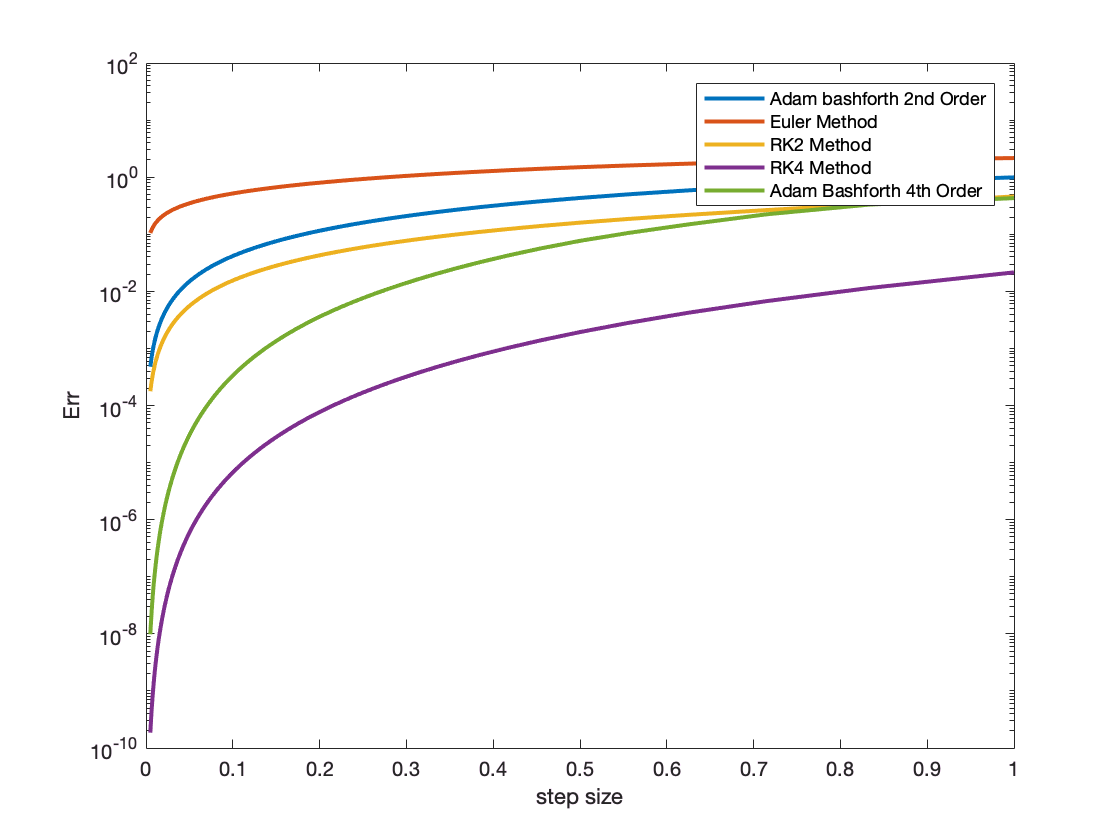


sts = 5./ns;
length(sts);
semilogy(sts, ab2_nlin_err, 'lineWidth', 2, 'DisplayName', 'Adam bashforth 2nd Order');
hold on;
semilogy(sts, euler_nlin_err, 'lineWidth', 2, 'DisplayName', 'Euler Method')
semilogy(sts, rk2_nlin_err, 'lineWidth', 2, 'DisplayName', 'RK2 Method')
semilogy(sts, rk4_nlin_err, 'lineWidth', 2, 'DisplayName', 'RK4 Method')
semilogy(sts, ab4_nlin_err, 'lineWidth', 2, 'DisplayName', 'Adam Bashforth 4th Order')
legend('show')
ylabel('Err')
xlabel('step size')
hold off;